## B Running HPC for LDE, then test LIF only

## 1. Setting up network

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'];
addpath(DataFolder)

### B1. Load LDE computations and do Fr distributions

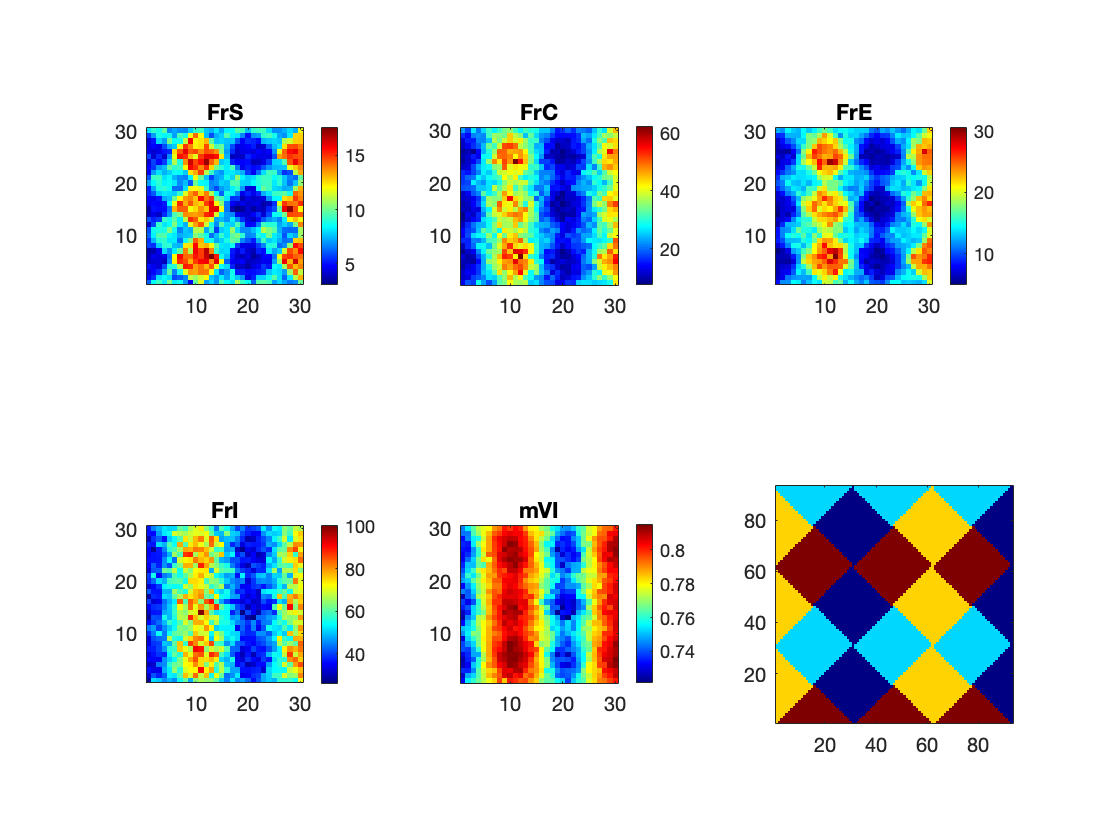

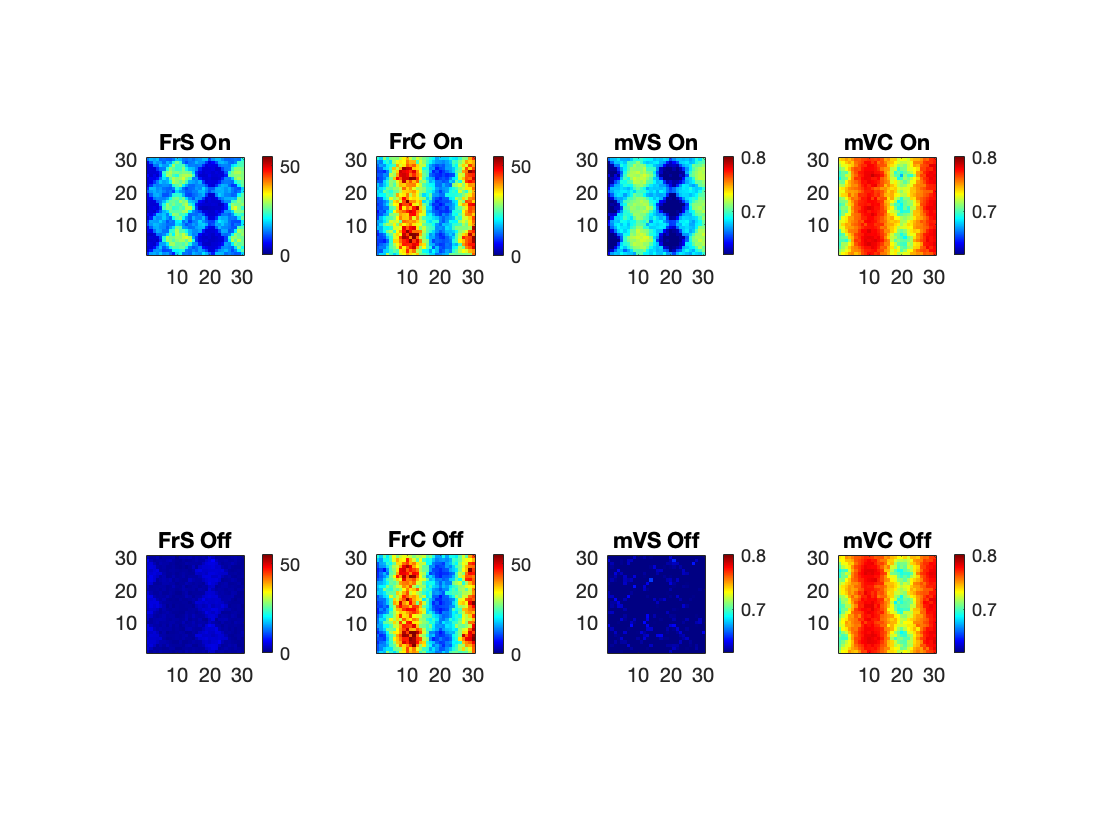

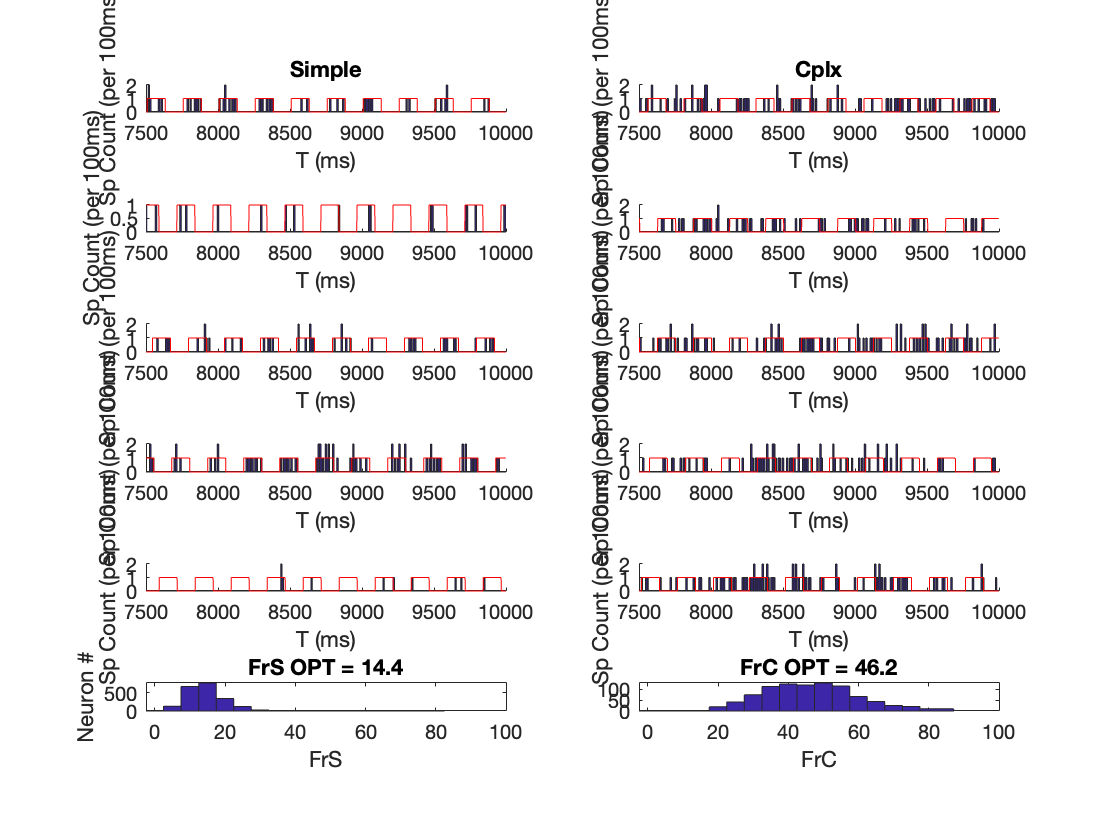

load("AllMFPixPara_Paper2TuneFig1V4.mat")

DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'];

OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = L6S_Pixel<1.1*min(L6S_Drive);  %lambda_SOn_Pixel<0.22;
OPTOBLBd_Pix = lambda_SOn_Pixel>0.33 & lambda_SOn_Pixel<0.42;
ORTOBLBd_Pix = lambda_SOn_Pixel>0.22 & lambda_SOn_Pixel<0.30;
NSPix = N_S/PixNum; NCPix = N_C/PixNum;
FrEPixNW = (FrSPixVec*NSPix + FrCPixVec*NCPix)/(NSPix+NCPix);
%FrEPixMF = (FrSMFV*NSPix + FrCMFV*NCPix)/(NSPix+NCPix);
fLDE_OPT = load([DataFolder 'Paper2_LDE3_Fig1V4.mat'],'f_EnIOut'); fLDE_OPT = fLDE_OPT.f_EnIOut;
fLDE_OBL = load([DataFolder 'Paper2_LDE2_Fig1V4.mat'],'f_EnIOut'); fLDE_OBL = fLDE_OBL.f_EnIOut;
fLDE_ORT = load([DataFolder 'Paper2_LDE1_Fig1V4.mat'],'f_EnIOut'); fLDE_ORT = fLDE_ORT.f_EnIOut;
FrLDE_opt = zeros(5,length(fLDE_OPT));
FrLDE_obl = zeros(5,length(fLDE_OPT));
FrLDE_ort = zeros(5,length(fLDE_OPT));
for LDEInd = 1:length(fLDE_OPT)
    if ~(isempty(fLDE_OPT{LDEInd}) || size(fLDE_OPT{LDEInd},2)<25)
        FrLDE_opt(:,LDEInd) = mean(fLDE_OPT{LDEInd}(:,end-25:end),2);
        FrLDE_obl(:,LDEInd) = mean(fLDE_OBL{LDEInd}(:,end-25:end),2);
        FrLDE_ort(:,LDEInd) = mean(fLDE_ORT{LDEInd}(:,end-25:end),2);
    else
        FrLDE_opt(:,LDEInd) = nan;
        FrLDE_obl(:,LDEInd) = nan;
        FrLDE_ort(:,LDEInd) = nan;
    end
end
FrLDE_opt(FrLDE_opt<0) = eps;
FrLDE_obl(FrLDE_obl<0) = eps;
FrLDE_ort(FrLDE_ort<0) = eps;
FrLDE_optE = ((FrLDE_opt(1,:)+FrLDE_opt(3,:))/2 * NSPix + ...
    (FrLDE_opt(2,:)+FrLDE_opt(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_oblE = ((FrLDE_obl(1,:)+FrLDE_obl(3,:))/2 * NSPix + ...
    (FrLDE_obl(2,:)+FrLDE_obl(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_ortE = ((FrLDE_ort(1,:)+FrLDE_ort(3,:))/2 * NSPix + ...
    (FrLDE_ort(2,:)+FrLDE_ort(4,:))/2 * NCPix)/(NSPix+NCPix);
% Do hist2
XOPT = linspace(12,51,30); YOPT = linspace(45,143,30);
NW_OPT = histcounts2(FrEPixNW(OPTPix),FrIPixVec(OPTPix),XOPT,YOPT);
LDE_OPT = histcounts2(FrLDE_optE,FrLDE_opt(5,:),XOPT,YOPT);
XOBL = linspace(5,32,30); YOBL = linspace(27,114,30);
NW_OBL = histcounts2(FrEPixNW(OBLPix),FrIPixVec(OBLPix),XOBL,YOBL);
LDE_OBL = histcounts2(FrLDE_oblE,FrLDE_obl(5,:),XOBL,YOBL);
XORT = linspace(2,20,30); YORT = linspace(14,92,30);
NW_ORT = histcounts2(FrEPixNW(ORTPix),FrIPixVec(ORTPix),XORT,YORT);
LDE_ORT = histcounts2(FrLDE_ortE,FrLDE_ort(5,:),XORT,YORT);


Figures for comparison

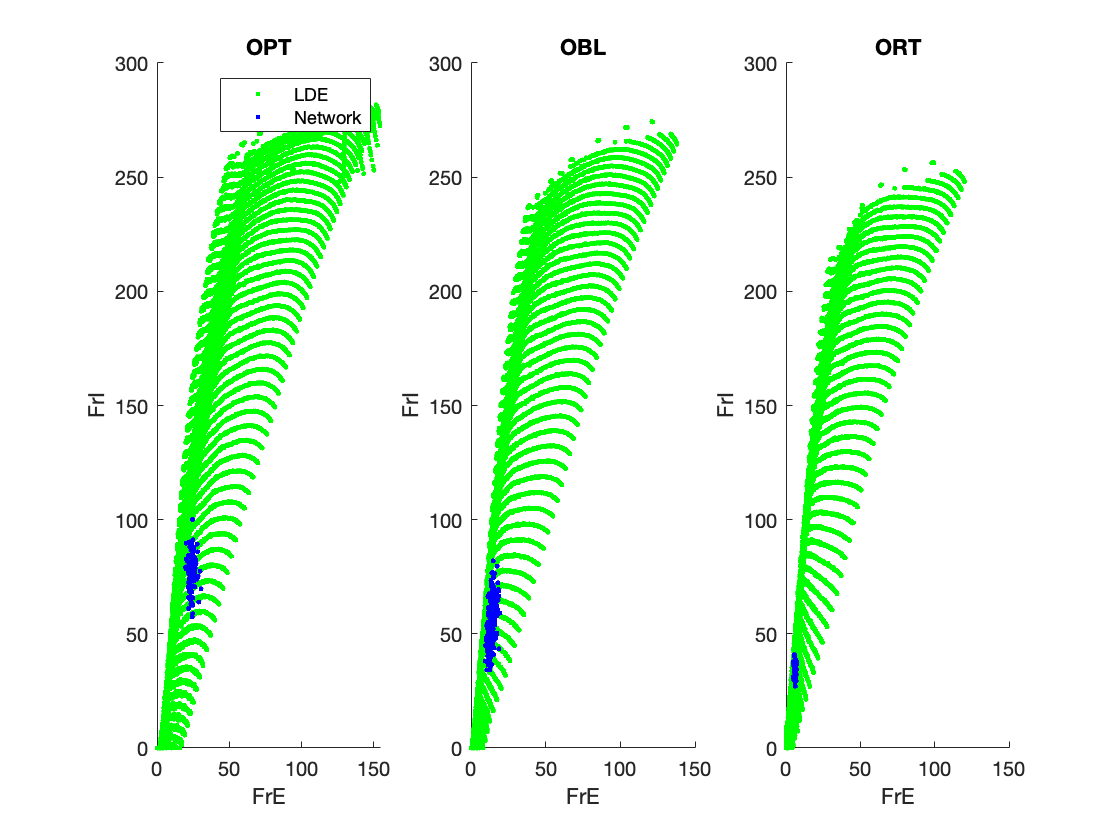

figure('Name','FrRanges')
subplot 131
hold on
scatter(FrLDE_optE,FrLDE_opt(5,:),'g.','DisplayName','LDE')
scatter(FrEPixNW(OPTPix),FrIPixVec(OPTPix),'b.','DisplayName','Network')
%scatter(FrEPixMF(OPTPix),FrIMFV(OPTPix),'r.','DisplayName','MF+V')
legend
xlabel('FrE');ylabel('FrI');
title('OPT')

subplot 132
hold on
scatter(FrLDE_oblE,FrLDE_obl(5,:),'g.')
scatter(FrEPixNW(OBLPix),FrIPixVec(OBLPix),'b.')
%scatter(FrEPixMF(OBLPix),FrIMFV(OBLPix),'r.')
xlabel('FrE');ylabel('FrI');
title('OBL')

subplot 133
hold on
scatter(FrLDE_ortE,FrLDE_ort(5,:),'g.')
scatter(FrEPixNW(ORTPix),FrIPixVec(ORTPix),'b.')
%scatter(FrEPixMF(ORTPix),FrIMFV(ORTPix),'r.')
xlabel('FrE');ylabel('FrI');
title('ORT')

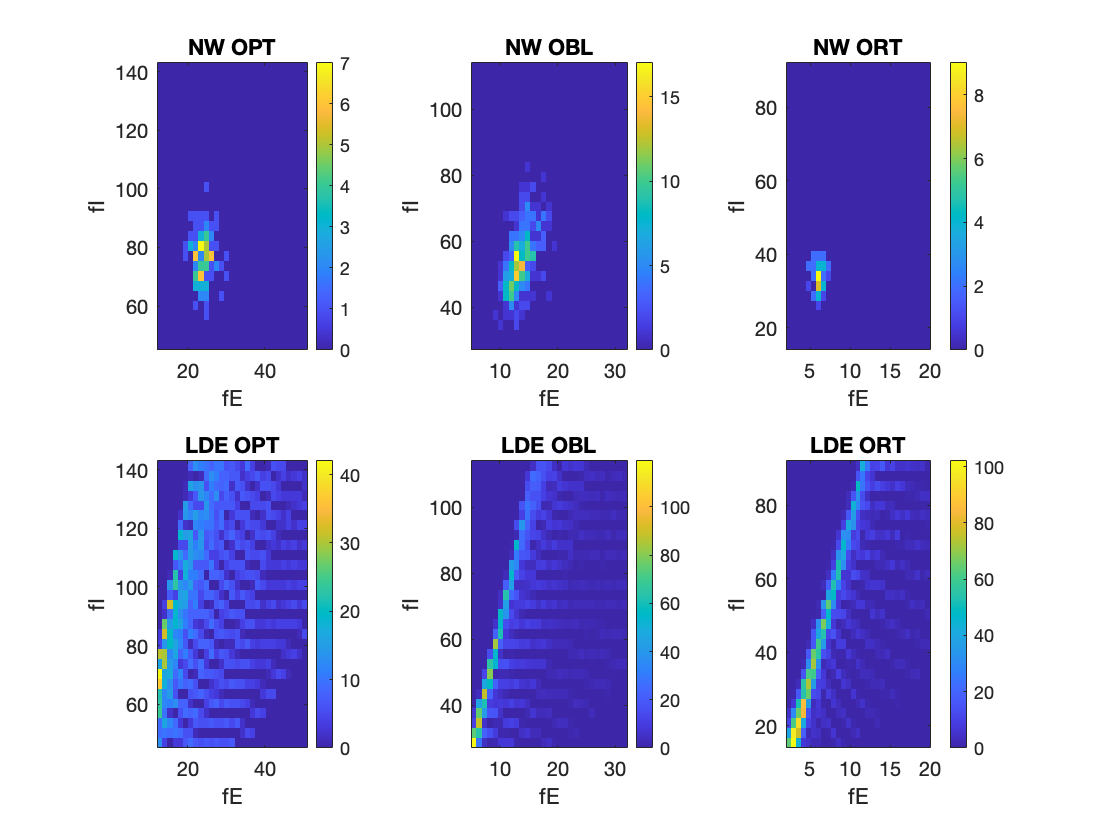


figure("Name",'FrDistb')
subplot 231
imagesc((XOPT(1:end-1)+XOPT(2:end))/2,(YOPT(1:end-1)+YOPT(2:end))/2,NW_OPT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OPT')
subplot 234
imagesc((XOPT(1:end-1)+XOPT(2:end))/2, (YOPT(1:end-1)+YOPT(2:end))/2, LDE_OPT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OPT')
subplot 232
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2, NW_OBL')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OBL')
subplot 235
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2,LDE_OBL')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OBL')
subplot 233
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,NW_ORT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW ORT')
subplot 236
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,LDE_ORT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE ORT')

## 2. Set up LDE firing rate functions

from HPC LDE computed results

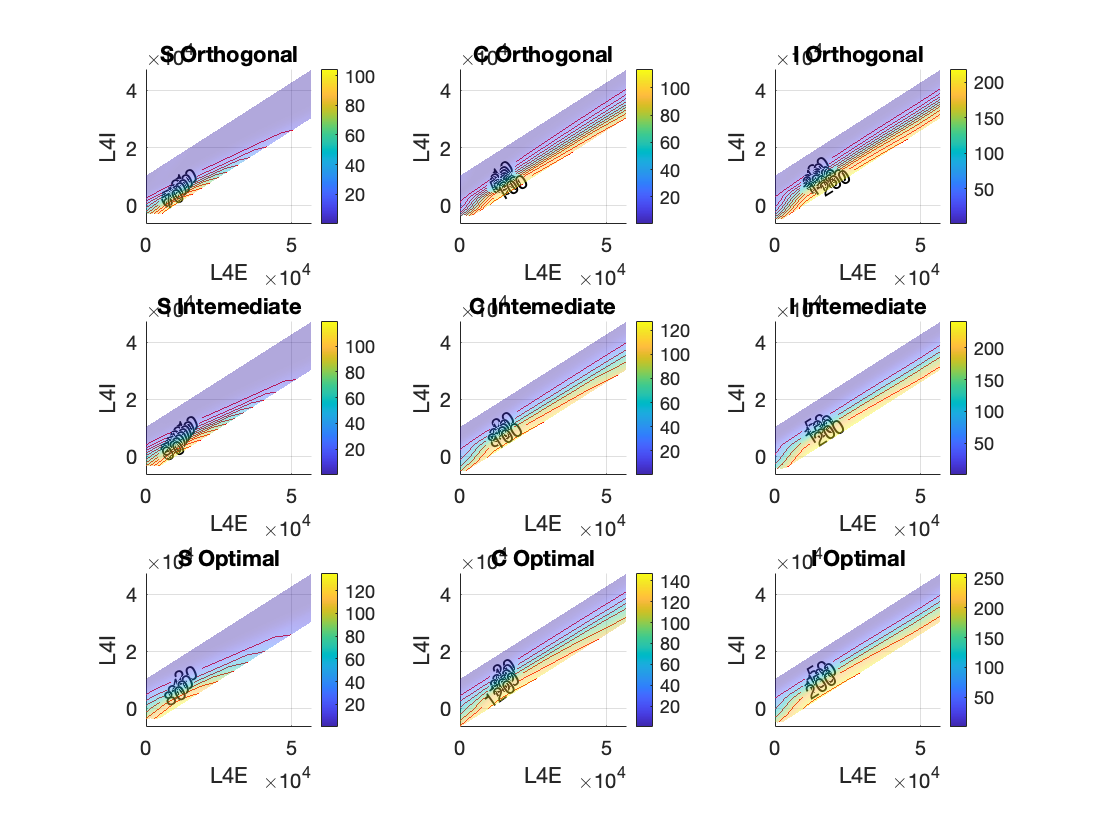

% Determine L4 Input from a range
% Expectation of kick numbers received by 1 neuron in each type
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
    L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
        - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
    L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
    L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
        - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
    L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
    L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
        - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
    L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
end
% Proportions between the distributions of kicks to SCI cells
% Assumption here: Total kicks received by the same pixel should be
% proportional to SCI
load(['Paper2_LDE1_Fig1V4.mat'])
a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);


figure('Name','LDERateFunctions')
CtgrName = {'Orthogonal','Intemediate','Optimal'};
LDEFrVecS = zeros(length(L4ERcrd),3);
LDEFrVecC = zeros(length(L4ERcrd),3);
LDEFrVecI = zeros(length(L4ERcrd),3);
for Ctgr = 1:3
    load(['Paper2_LDE' num2str(Ctgr) '_Fig1V4.mat'])
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),5);
    for LDEInd = 1:length(f_EnIOut)
        if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<25)
            FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,end-25:end),2))';
        else
            FrLDE(LDEInd,:) = nan;
        end
    end
    FrLDE(FrLDE<0) = eps;
    % S rates
    subplot(3,3,(Ctgr-1)*3+1)
    LDEFrVecS(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true);

    % C rates
    subplot(3,3,(Ctgr-1)*3+2)
    LDEFrVecC(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'C',true);

    % I rates
    subplot(3,3,(Ctgr-1)*3+3)
    LDEFrVecI(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'I',true);
end

Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
% 2D function now, depending on input of total E and I kick numbers
LDEFrfunc.S.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.C.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.I.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,3),L4EmeshX, L4ImeshY);

Maybe linear extrapolation?

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 3; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

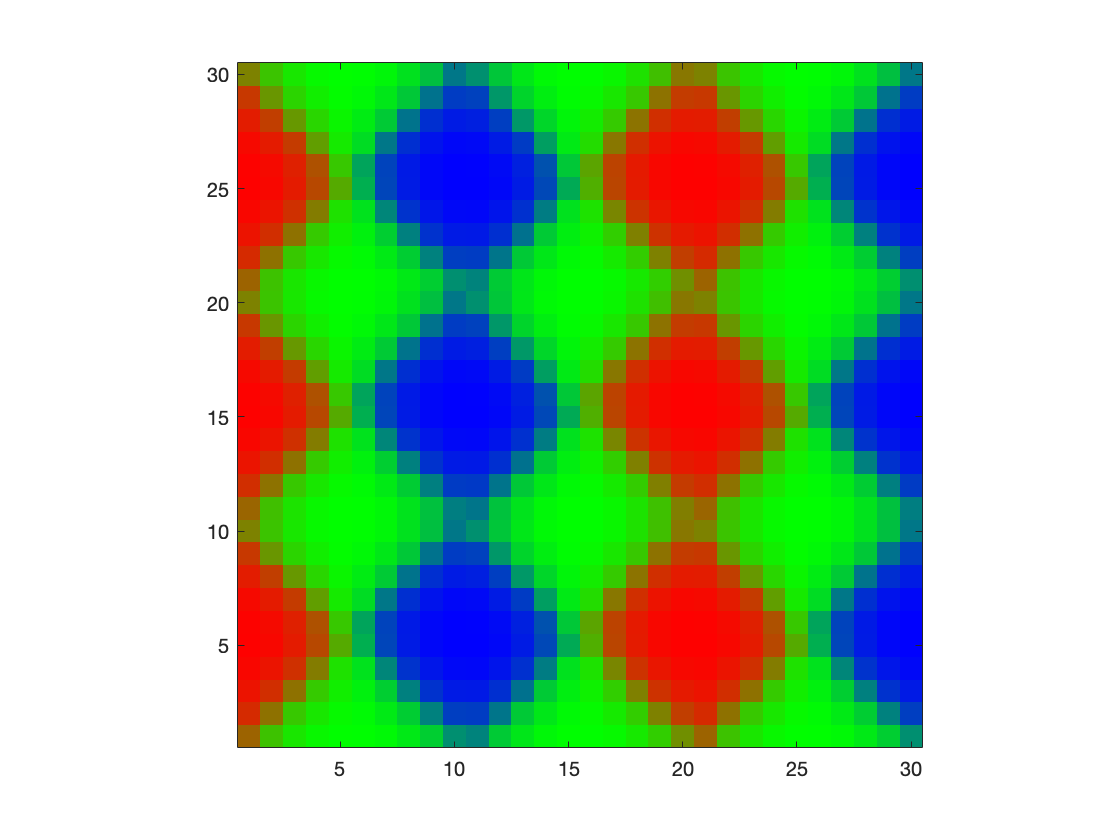

PixL6Ctgr = LGNIndSpat(L6SFilt,unique(L6S_Drive),NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(PhaseFRS(OD_S)',unique(PhaseFRS(OD_S)),NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixInptCtgr = PixL6Ctgr*0.7 + PixLGNCtgr*0.3;

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
% Classify Input for each pixel
% Get input spatial pattern for 3*3 and make a larger one

% PixCtgr = ORTPix + 2*OBLPix + 3*OPTPix + 4*ORTOBLBd_Pix + 5*OPTOBLBd_Pix;
% PixCtgrBool = [ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix];
figure('Name','function applying')
ShowField(PixInptCtgr,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY)


% CtgrMap = [0,0,0.5; 0.5,0,0; 0,0.5,0; 1,0,1; 1,1,0];
% cbr = colorbar; cbr.Ticks = 1:5; cbr.TickLabels = {'ORT','OBL','OPT','Bdry12','Bdry23'};
% colormap(CtgrMap)

Give an intial condition, Now start

try a dot product here

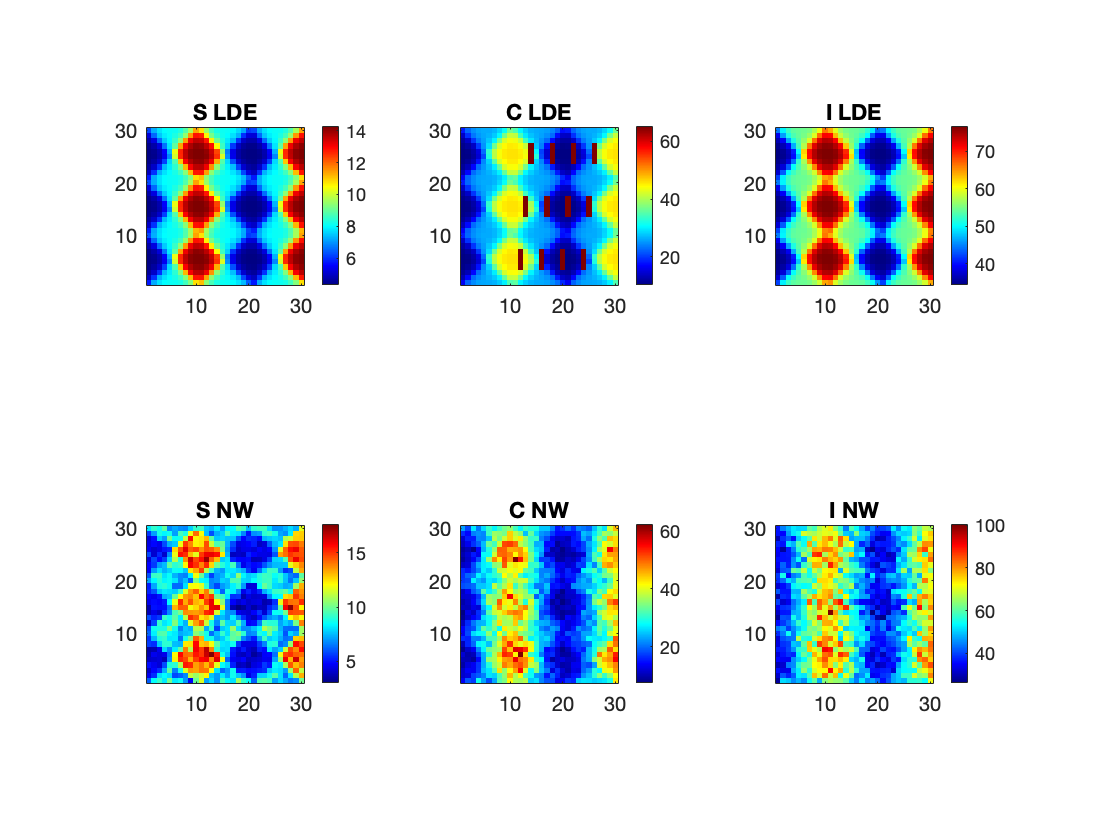

ORTPixLar = PixInptCtgr(:,1) == 1;
OBLPixLar = PixInptCtgr(:,2) == 1;
OPTPixLar = PixInptCtgr(:,3) == 1;
MeanFrCtry = @(x1) [mean(x1(ORTPix)),mean(x1(OBLPix)),mean(x1(OPTPix))];

LDEIni.S = PixInptCtgr * MeanFrCtry(FrSPixVec)';
LDEIni.C = PixInptCtgr * MeanFrCtry(FrCPixVec)';
LDEIni.I = PixInptCtgr * MeanFrCtry(FrIPixVec)';
% LDEIni.S = ORTPix*mean(FrSPixVec(ORTPix)) + OBLPix*mean(FrSPixVec(OBLPix)) + ...
%            OPTPix*mean(FrSPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrSPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrSPixVec(OPTOBLBd_Pix));
% LDEIni.C = ORTPix*mean(FrCPixVec(ORTPix)) + OBLPix*mean(FrCPixVec(OBLPix)) + ...
%            OPTPix*mean(FrCPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrCPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrCPixVec(OPTOBLBd_Pix));
% LDEIni.I = ORTPix*mean(FrIPixVec(ORTPix)) + OBLPix*mean(FrIPixVec(OBLPix)) + ...
%            OPTPix*mean(FrIPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrIPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrIPixVec(OPTOBLBd_Pix));

for IndX = 9:20
    for IndY = 14:17
        PixInd = (IndX-1)*40 + IndY;
        LDEIni.C(PixInd) = 65;
    end
end
% LDEIni.S = ones(size(LDEIni.S))*mean(LDEIni.S,'all')*2/3;
% LDEIni.C = ones(size(LDEIni.C))*mean(LDEIni.C,'all')*2/3;
% LDEIni.I = ones(size(LDEIni.I))*mean(LDEIni.I,'all')*2/3;
% LDEIni.S = FrSPixVec;
% LDEIni.C = FrCPixVec;
% LDEIni.I = FrIPixVec;
figure('Name','LDE Initial')
subplot 231
ShowField(LDEIni.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 232
ShowField(LDEIni.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 233
ShowField(LDEIni.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 234
ShowField(FrSPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S NW')
subplot 235
ShowField(FrCPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C NW')
subplot 236
ShowField(FrIPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I NW')

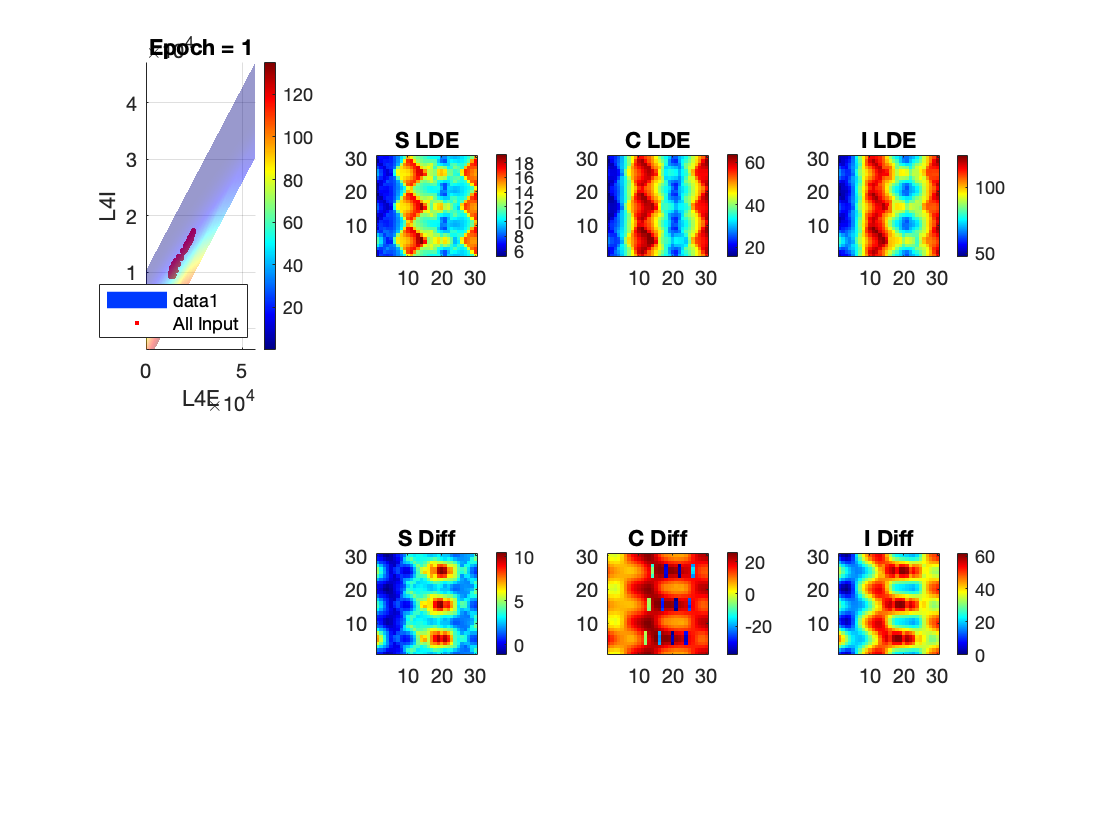

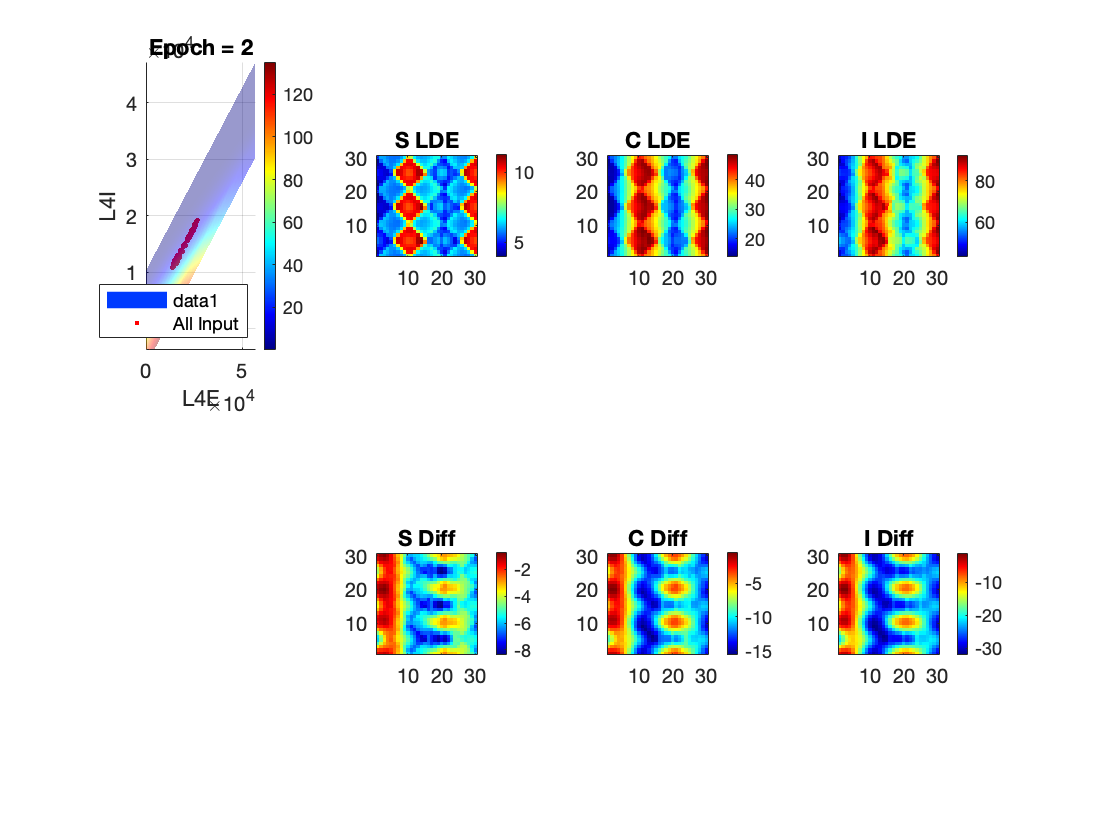

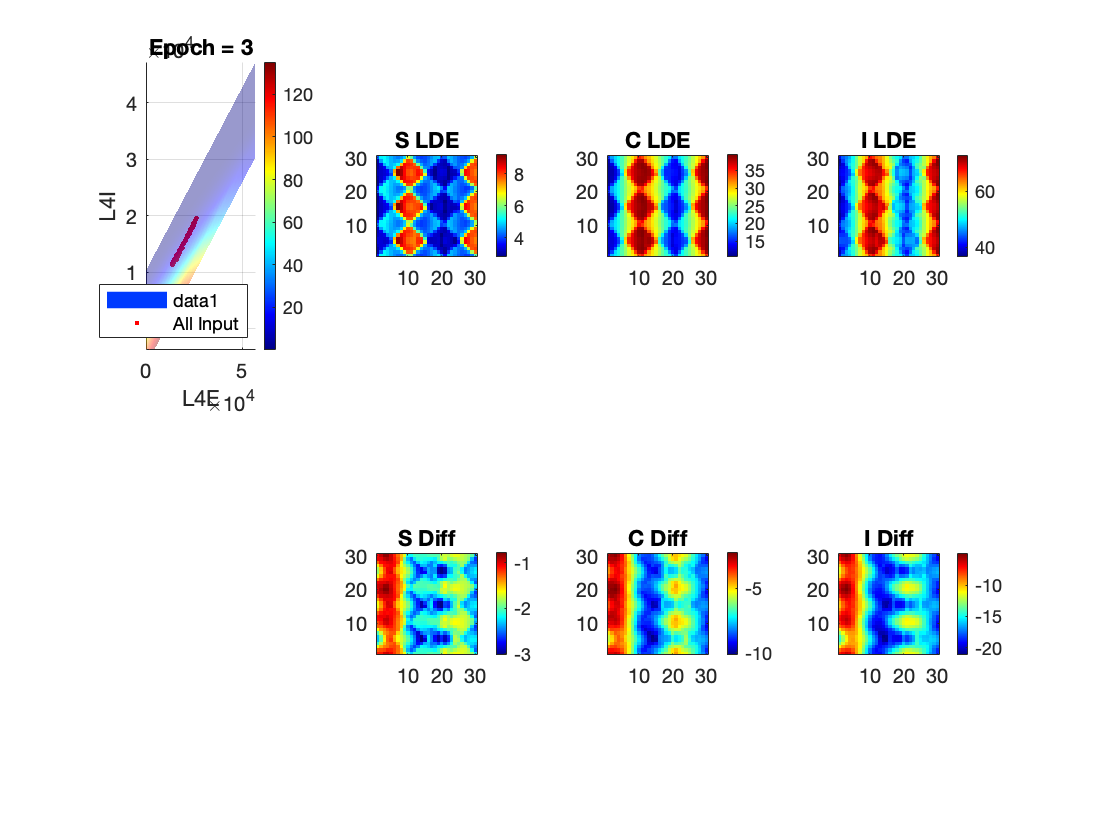

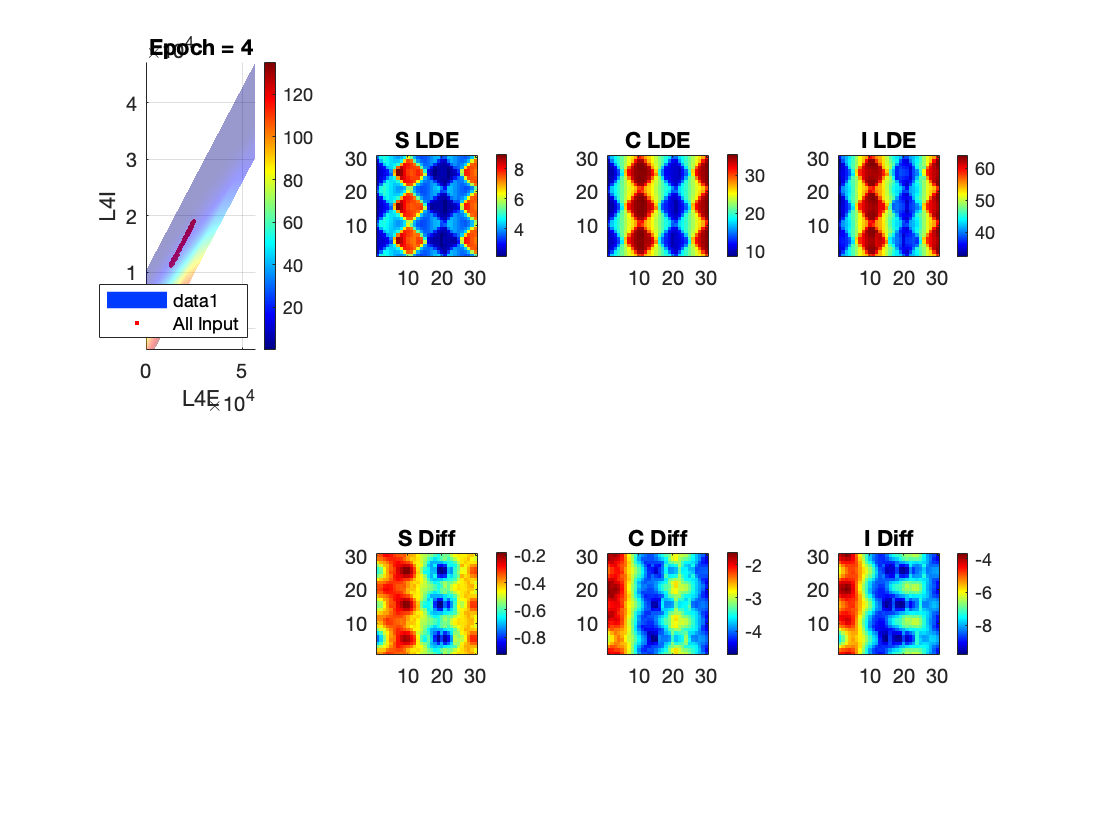

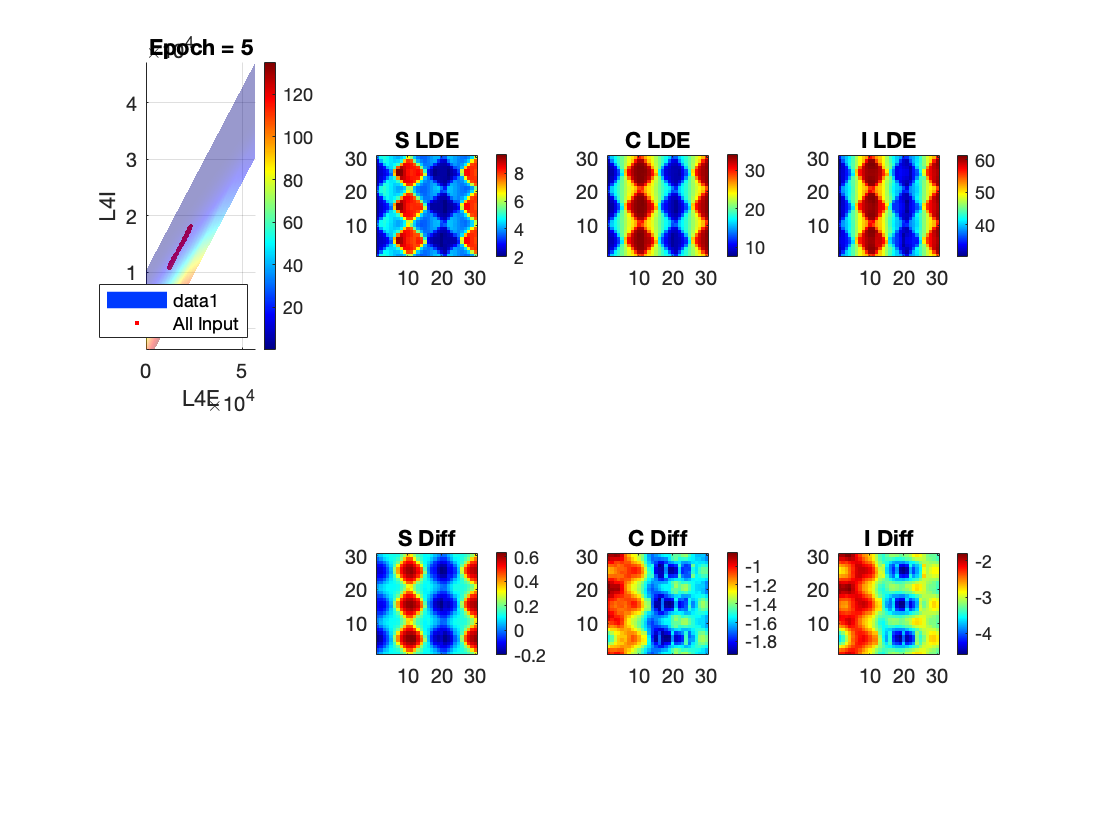

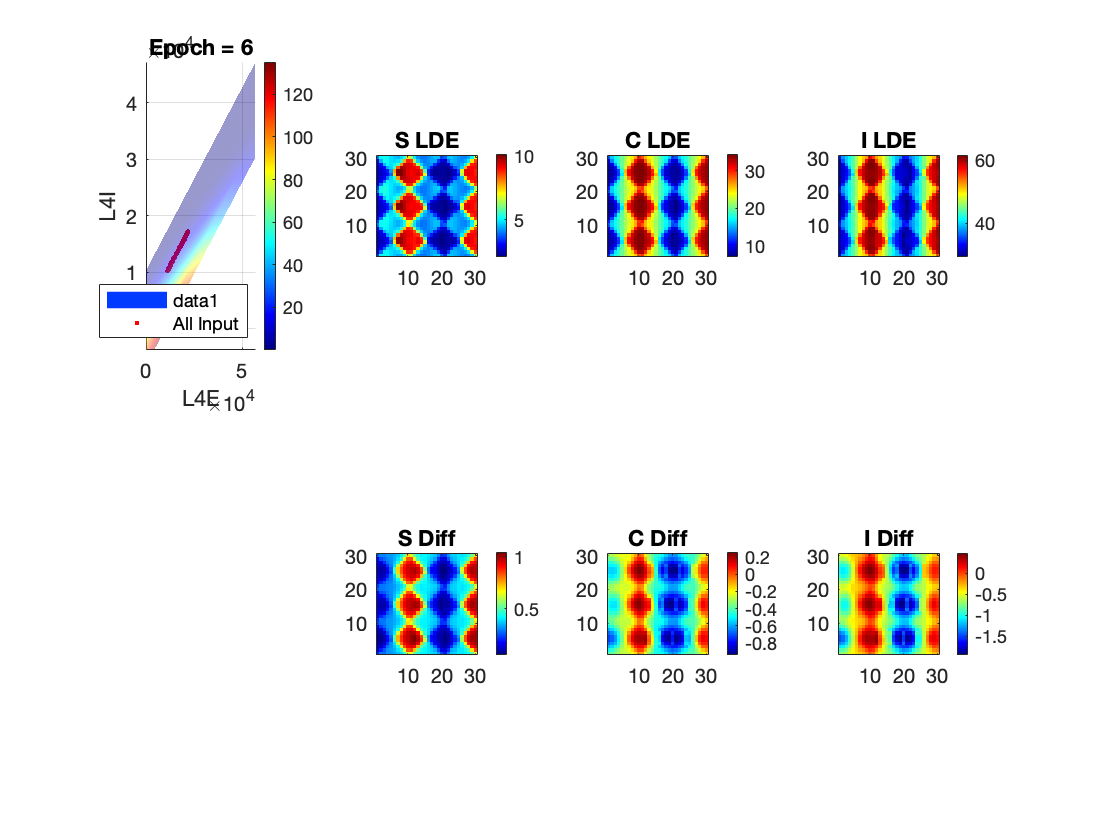

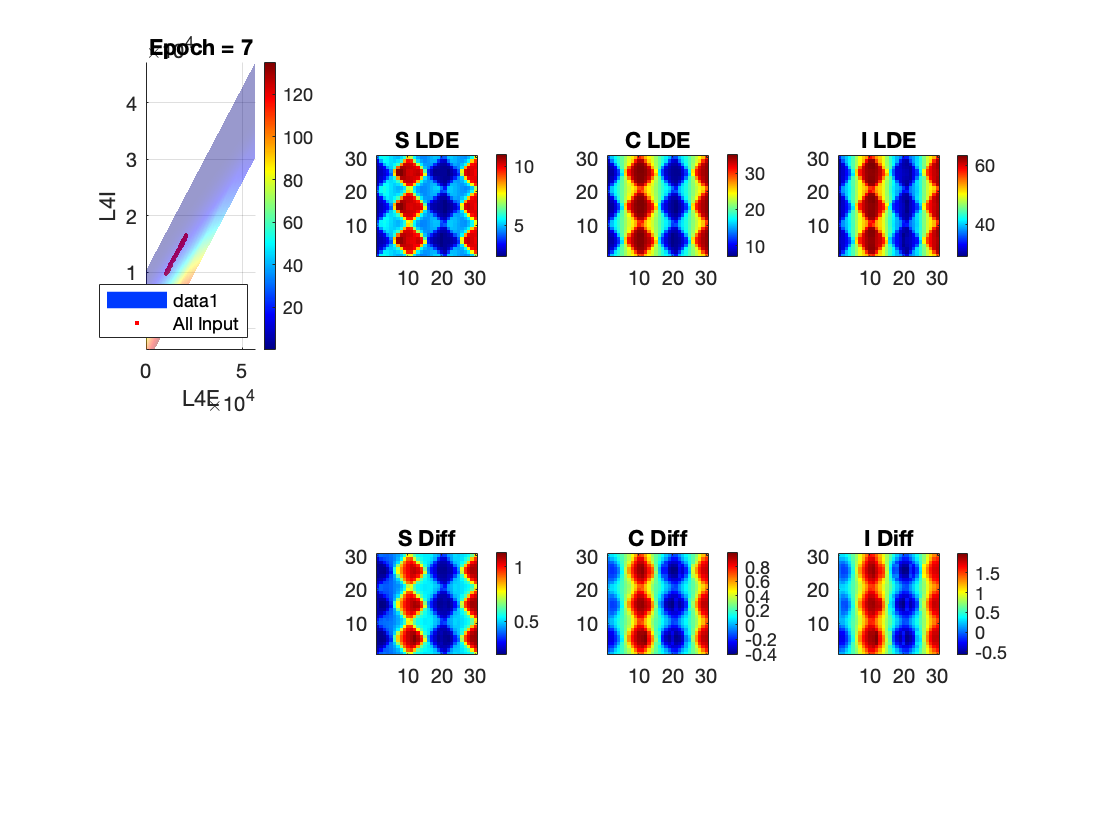

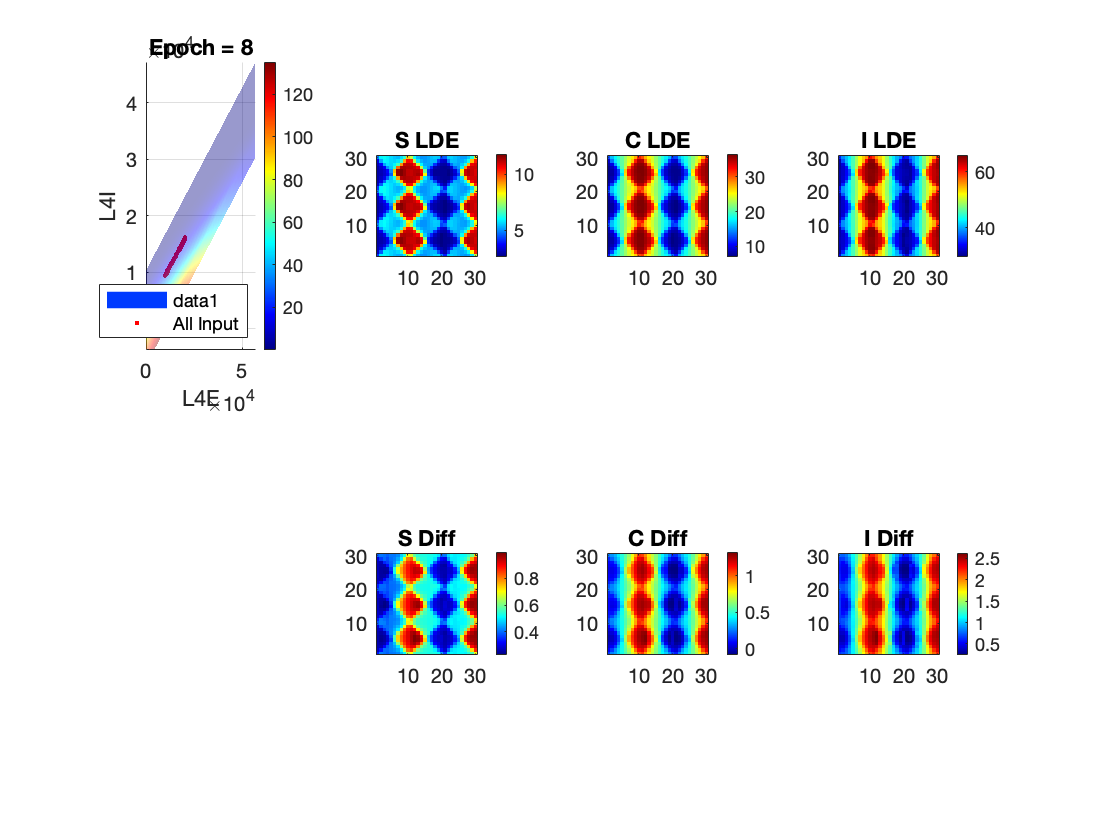

% Iteration
p = 0.2; % 1-p for the original input
Epoc = 20;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;

for Epc = 1:Epoc
    figure('Name','LDE Iteration')
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S  - diag(C_SS_mean).*LDEUse.S + ...
        C_CS_mean*LDEUse.S  - diag(C_CS_mean).*LDEUse.S + ...
        C_IS_mean*LDEUse.S  - diag(C_IS_mean).*LDEUse.S + ...
        C_SC_mean*LDEUse.C  - diag(C_SC_mean).*LDEUse.C + ...
        C_CC_mean*LDEUse.C  - diag(C_CC_mean).*LDEUse.C + ...
        C_IC_mean*LDEUse.C  - diag(C_IC_mean).*LDEUse.C ;
    L4IUse = C_SI_mean*LDEUse.I  - diag(C_SI_mean).*LDEUse.I + ...
        C_CI_mean*LDEUse.I  - diag(C_CI_mean).*LDEUse.I + ...
        C_II_mean*LDEUse.I  - diag(C_II_mean).*LDEUse.I ;
    % See where does the input stands
    subplot 241
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true,false);
    hold on
    scatter(L4EUse,L4IUse,'r.','Displayname','All Input');
    %     scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
    %     scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
    %     scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
    %     scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
    %     scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
    legend('Location','southeast')
    title(sprintf('Epoch = %d', Epc))
    hold off
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
        L4EUse,L4IUse,LDEUse.S,...
        PixInptCtgr);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
        L4EUse,L4IUse,LDEUse.C,...
        PixInptCtgr);
    % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
        L4EUse,L4IUse,LDEUse.I,...
        PixInptCtgr);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct('S',LDEOut.S*p + LDEUse.S*(1-p),...
        'C',LDEOut.C*p + LDEUse.C*(1-p),...
        'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
    subplot 242
    ShowField(LDEOut.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
    subplot 243
    ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
    subplot 244
    ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
    subplot 246
    ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S Diff')
    subplot 247
    ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C Diff')
    subplot 248
    ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')
    drawnow
    pause(0.5)
end

One more fig for diff

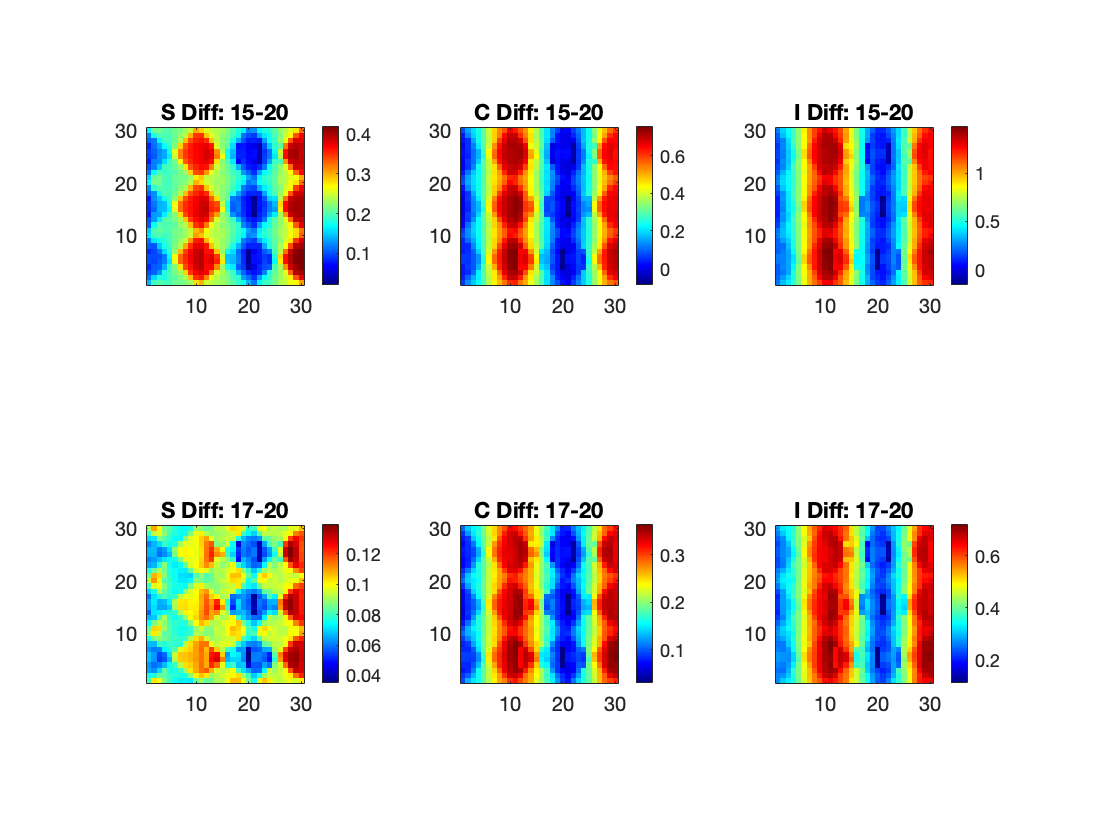

figure('Name','epoch diff')
subplot 231
Ep1 = 15; Ep2 = 17; Ep3 = 20;
ShowField(LDEEpoOut{Ep1}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep1, Ep3))
subplot 232
ShowField(LDEEpoOut{Ep1}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep1, Ep3))
subplot 233
ShowField(LDEEpoOut{Ep1}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep1, Ep3))

subplot 234
ShowField(LDEEpoOut{Ep2}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep2, Ep3))
subplot 235
ShowField(LDEEpoOut{Ep2}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep2, Ep3))
subplot 236
ShowField(LDEEpoOut{Ep2}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep2, Ep3))

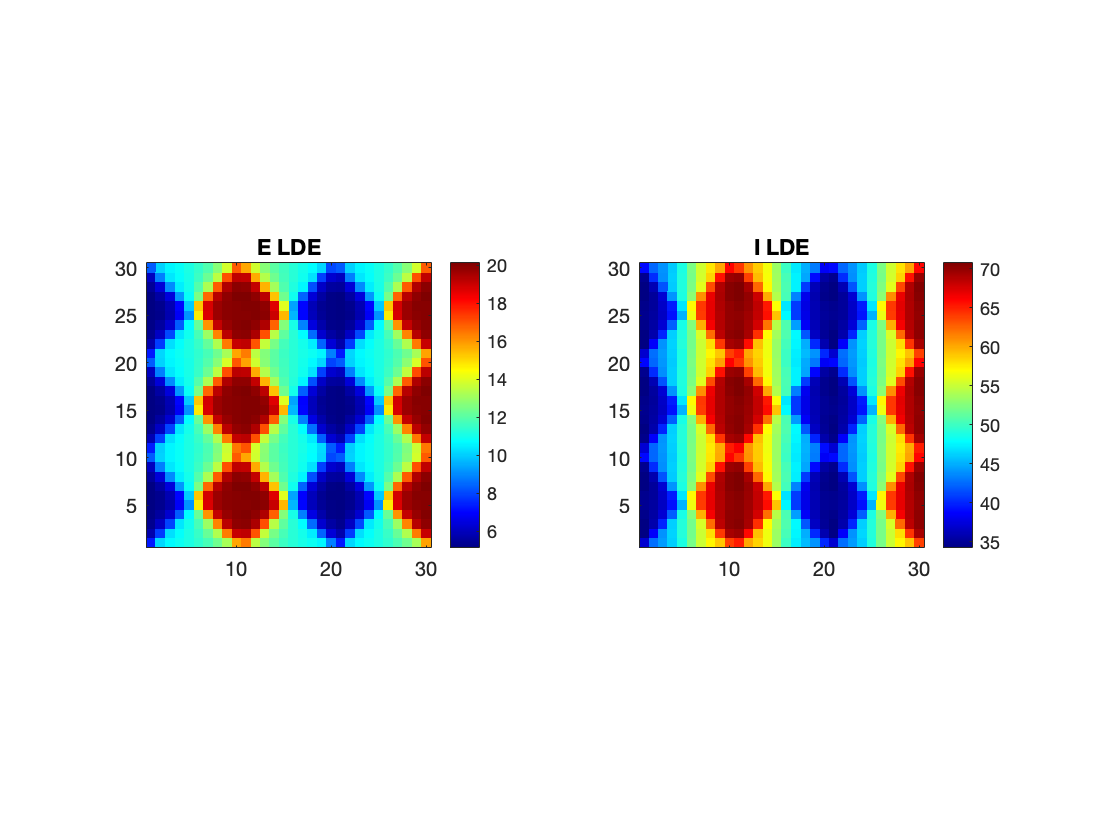


figure('Name','EImap')
subplot 121
ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'E LDE')
subplot 122
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')

 Compute Frs

LDENames = fieldnames(LDEOut)

LDENames = 3×1 cell array
    {'S'}
    {'C'}
    {'I'}


for Nid = 1:length(LDENames)
    CurrField = LDEOut.(LDENames{Nid});
    CurrMap = reshape(CurrField,N_HCOut*NPixX,N_HCOut*NPixY);
    CurrMapShrk = CurrMap(1:N_HC*NPixY,1:N_HC*NPixX);
    LDEOutShrk.(LDENames{Nid}) = reshape(CurrMapShrk,N_HC*NPixY*N_HC*NPixX,1);
    MeanFrCtry(LDEOutShrk.(LDENames{Nid}))
end

ans =     3.7302    6.3250   11.7799


ans =     8.5870   23.4774   38.1605


ans =    34.9351   51.1870   69.3826


### 4. Comparison between MF+V and LIF-only

L4lifSE = C_SS_Pixel_Us*FrSPixVec + C_SC_Pixel_Us*FrCPixVec;
L4lifSI = C_SI_Pixel_Us*FrIPixVec ;
L4lifCE = C_CS_Pixel_Us*FrSPixVec + C_CC_Pixel_Us*FrCPixVec;
L4lifCI = C_CI_Pixel_Us*FrIPixVec ;
L4lifIE = C_IS_Pixel_Us*FrSPixVec + C_IC_Pixel_Us*FrCPixVec;
L4lifII = C_II_Pixel_Us*FrIPixVec ;
L4localSE = diag(C_SS_Pixel_Us).*FrSPixVec + diag(C_SC_Pixel_Us).*FrCPixVec;
L4localSI = diag(C_SI_Pixel_Us).*FrIPixVec ;
L4localCE = diag(C_CS_Pixel_Us).*FrSPixVec + diag(C_CC_Pixel_Us).*FrCPixVec;
L4localCI = diag(C_CI_Pixel_Us).*FrIPixVec ;
L4localIE = diag(C_IS_Pixel_Us).*FrSPixVec + diag(C_IC_Pixel_Us).*FrCPixVec;
L4localII = diag(C_II_Pixel_Us).*FrIPixVec ;
L4EmfvUse = C_SS_Pixel_Us*FrSPixVec  - diag(C_SS_Pixel_Us).*FrSPixVec + ...
            C_CS_Pixel_Us*FrSPixVec  - diag(C_CS_Pixel_Us).*FrSPixVec + ...
            C_IS_Pixel_Us*FrSPixVec  - diag(C_IS_Pixel_Us).*FrSPixVec + ...
            C_SC_Pixel_Us*FrCPixVec  - diag(C_SC_Pixel_Us).*FrCPixVec + ...
            C_CC_Pixel_Us*FrCPixVec  - diag(C_CC_Pixel_Us).*FrCPixVec + ...
            C_IC_Pixel_Us*FrCPixVec  - diag(C_IC_Pixel_Us).*FrCPixVec ;
L4ImfvUse = C_SI_Pixel_Us*FrIPixVec  - diag(C_SI_Pixel_Us).*FrIPixVec + ...
            C_CI_Pixel_Us*FrIPixVec  - diag(C_CI_Pixel_Us).*FrIPixVec + ...
            C_II_Pixel_Us*FrIPixVec  - diag(C_II_Pixel_Us).*FrIPixVec ;

Now consider a pixel containing 3 neurons: S C I

Pick up 10 pixels

%InputCtgrList = [1,1, 1,  2,  2,  2,   3,  3,   3];
%PixRow = [5,5,25,  1,10,20,  5,15,5 ];
PixRow = randi([1,30],50,1);
%PixCol = [1,20,20, 15,15,26, 10,10,29];
PixCol = randi([1,30],50,1);
PixIndList = (PixCol-1)*N_HC*NPixY +  PixRow ;% [7,55,615,180,450,645, 565,326, 276];
VRcdAll = cell(size(PixIndList));
SpRcdAll = cell(size(PixIndList));
FrRcdAve = zeros(length(PixIndList),3);

for LIFtestInd = 1:length(PixIndList)
%InputCtgr = InputCtgrList(LIFtestInd); 
PixInd = PixIndList(LIFtestInd); % pixel and input category

FL6_One = unique(L6Ord_F)/1e3;
rL6SU = L6S_Pixel(PixInd);
rL6CU = L6C_Pixel(PixInd);
rL6IU = L6I_Pixel(PixInd);
L4SE = L4lifSE(PixInd)/1e3*(1-p_EEFail); L4CE = L4lifCE(PixInd)/1e3*(1-p_EEFail); L4IE = L4lifIE(PixInd)/1e3;
L4SI = L4lifSI(PixInd)/1e3;              L4CI = L4lifCI(PixInd)/1e3;              L4II = L4lifII(PixInd)/1e3;

LIFSimuT = 50*1e3; TimeFrac = 1/(LIFSimuT/1e3)/LGNFreq;
lgn_Events    = PoissonInputForNetwork(3, 45*[N_Slgn;N_Clgn;N_Ilgn]/1e3 ,LIFSimuT*TimeFrac,dt,true);
AmbPix_Events = PoissonInputForNetwork(3,[rS_amb;rC_amb;rI_amb],LIFSimuT*TimeFrac,dt,true);
L6Pix_Events  = PoissonInputForNetwork(3,[rL6SU; rL6CU; rL6IU], LIFSimuT*TimeFrac,dt,true);
L4Pix_EventsE = PoissonInputForNetwork(3,[L4SE; L4CE; L4IE],LIFSimuT*TimeFrac,dt,true);
L4Pix_EventsI = PoissonInputForNetwork(3,[L4SI; L4CI; L4II],LIFSimuT*TimeFrac,dt,true);
gL = [gL_E*ones(2,1); gL_I*ones(1)];

Can precompute all Gs...

% Now adjust lgn to S
lgn_SOnOff = [0.045, 0.0675, 0.09;
              0.045, 0.0225, 0.00];
lgn_Slif = [lambda_SOn_Pixel';lambda_SOff_Pixel'];
lgn_Slifort = mean(mean(lgn_Slif))*ones(2,1);

lgnAdj = lgn_Slif(:,PixInd)./lgn_Slifort;
lgnAdjU = reshape(repmat(lgnAdj,1,floor(size(L4Pix_EventsE,2)/2))', 1, 2*floor(size(L4Pix_EventsE,2)/2));

Disp some # of spikes

sprintf('#L6 = %.4f', sum(FL6_One.*PixL6Ctgr(PixInd,:)))
sprintf('#L4SE total = %.4f, #L4SI total = %.4f',L4lifSE(PixInd)/1e3,L4lifSI(PixInd)/1e3)
sprintf('#L4CE total = %.4f, #L4CI total = %.4f',L4lifCE(PixInd)/1e3,L4lifCI(PixInd)/1e3)
sprintf('#L4IE total = %.4f, #L4II total = %.4f',L4lifIE(PixInd)/1e3,L4lifII(PixInd)/1e3)
sprintf('#L4SE local = %.4f, #L4SI local = %.4f',L4localSE(PixInd)/1e3,L4localSI(PixInd)/1e3)
sprintf('#L4CE local = %.4f, #L4CI local = %.4f',L4localCE(PixInd)/1e3,L4localCI(PixInd)/1e3)
sprintf('#L4IE local = %.4f, #L4II local = %.4f',L4localIE(PixInd)/1e3,L4localII(PixInd)/1e3)
% For each cycle, initiate a new start
TCyc = floor(1/TimeFrac);
VRcdCyc = cell(TCyc,1);
SpRcdCyc = cell(TCyc,1);

RefTimer = zeros(3, 1); % initiate the timer of ref
vt = zeros(3, 1); 
tic
for TInt = 1:TCyc
    VRcd = zeros(size(L4Pix_EventsE));
    SpLIF = zeros(3, 1);

    % New Gs
    lgnPix_Events = lgn_Events(:,randperm(size(lgn_Events,2)));
    lgnPix_Events(1,1:length(lgnAdjU)) = lgnPix_Events(1,1:length(lgnAdjU)).*lgnAdjU;

    winAMPA = 0:dt:tau_ampa_D*3;
    winNMDA = 0:dt:tau_nmda_D*3;
    winGABA = 0:dt:tau_gaba_D*3;
    KerAMPA = 1/(tau_ampa_D-tau_ampa_R) * (exp(-winAMPA/tau_ampa_D) - exp(-winAMPA/tau_ampa_R));
    KerNMDA = 1/(tau_nmda_D-tau_nmda_R) * (exp(-winNMDA/tau_nmda_D) - exp(-winNMDA/tau_nmda_R));
    KerGABA = 1/(tau_gaba_D-tau_gaba_R) * (exp(-winGABA/tau_gaba_D) - exp(-winGABA/tau_gaba_R));
    KerAMPA = KerAMPA / (sum(KerAMPA)*dt);
    KerNMDA = KerNMDA / (sum(KerNMDA)*dt);
    KerGABA = KerGABA / (sum(KerGABA)*dt);
    % Incorporate L4 and other input
    ampaInp = single([S_Elgn * lgnPix_Events(1:2,:);            S_Ilgn * lgnPix_Events(3,:)]...
        +  S_amb  * AmbPix_Events ... % S_amb identical for E and I
        + [S_EL6  * L6Pix_Events(1:2,:) * rhoE_ampa; S_IL6 * L6Pix_Events(3,:) * rhoI_ampa]...
        + [S_EE * L4Pix_EventsE(1:2,:) * rhoE_ampa; S_IE * L4Pix_EventsE(3,:) * rhoI_ampa]);
    nmdaInp = single([S_EL6  * L6Pix_Events(1:2,:) * rhoE_nmda; S_IL6 * L6Pix_Events(3,:) * rhoI_nmda]...
        + [S_EE * L4Pix_EventsE(1:2,:) * rhoE_nmda; S_IE * L4Pix_EventsE(3,:) * rhoI_nmda]);
    gabaInp = single([S_EI * L4Pix_EventsI(1:2,:);             S_II * L4Pix_EventsI(3,:)] );
    %% Precompute All Conductances: Speed up by ifft/fft
    n = size(ampaInp,2);
    GAMPA = ifft(fft(ampaInp',n) .* repmat(fft(KerAMPA',n),1,3))';
    GNMDA = ifft(fft(nmdaInp',n) .* repmat(fft(KerNMDA',n),1,3))';
    GGABA = ifft(fft(gabaInp',n) .* repmat(fft(KerGABA',n),1,3))';

    GE = GAMPA + GNMDA;  GI = GGABA;
    
    for tInd = 1:size(L4Pix_EventsE,2)
        % Firstly, refrectory neurons get out if timer reachs t_ref
        RefTimer(isnan(vt)) = RefTimer(isnan(vt)) + dt;
        vt(RefTimer>=tau_ref) = 0;
        RefTimer(RefTimer>=tau_ref) = 0;

        ov  = vt + dt*(-gL.*vt - GE(:,tInd).*(vt-Ve) - GI(:,tInd).*(vt-Vi));
        SpNow = single(ov>=1);
        ov(ov>=1) = nan;
        VRcd(:,tInd) = ov;
        % Compute meanV
            SpLIF = SpLIF + SpNow;
        % Transfer variables
        vt = ov;
    end
    VRcdCyc{TInt} = VRcd;
    SpRcdCyc{TInt} = SpLIF;
end
toc
VRcdAll{LIFtestInd} = VRcdCyc;
SpRcdAll{LIFtestInd} = SpRcdCyc;
SpRcdMat = cell2mat(SpRcdCyc')';
FrRcdAve(LIFtestInd,:) = mean(SpRcdMat(10:end,:))*LGNFreq; % The actual firing rates
%LDEresults = zeros(length(FrSPixVec),3);
end

Now for LDE results

DirLDEresults(:,1) = ...

ans = '#L6 = 0.0367'

ans = '#L4SE total = 3.2637, #L4SI total = 5.4411'

ans = '#L4CE total = 4.3708, #L4CI total = 5.4094'

ans = '#L4IE total = 14.3682, #L4II total = 5.3547'

ans = '#L4SE local = 0.0552, #L4SI local = 0.2564'

ans = '#L4CE local = 0.0570, #L4CI local = 0.2296'

ans = '#L4IE local = 0.2144, #L4II local = 0.2126'

Elapsed time is 3.095082 seconds.


ans = '#L6 = 0.0493'

ans = '#L4SE total = 3.8644, #L4SI total = 6.2460'

ans = '#L4CE total = 5.1483, #L4CI total = 6.2811'

ans = '#L4IE total = 16.8371, #L4II total = 6.1933'

ans = '#L4SE local = 0.0936, #L4SI local = 0.2505'

ans = '#L4CE local = 0.1110, #L4CI local = 0.1994'

ans = '#L4IE local = 0.3432, #L4II local = 0.2908'

Elapsed time is 2.976903 seconds.


ans = '#L6 = 0.0333'

ans = '#L4SE total = 3.1607, #L4SI total = 5.3261'

ans = '#L4CE total = 4.2820, #L4CI total = 5.2753'

ans = '#L4IE total = 14.0438, #L4II total = 5.1701'

ans = '#L4SE local = 0.0436, #L4SI local = 0.2189'

ans = '#L4CE local = 0.0478, #L4CI local = 0.2103'

ans = '#L4IE local = 0.2667, #L4II local = 0.1775'

Elapsed time is 2.982341 seconds.


ans = '#L6 = 0.0182'

ans = '#L4SE total = 1.8964, #L4SI total = 3.4181'

ans = '#L4CE total = 2.5963, #L4CI total = 3.4804'

ans = '#L4IE total = 8.5638, #L4II total = 3.3793'

ans = '#L4SE local = 0.0301, #L4SI local = 0.1487'

ans = '#L4CE local = 0.0446, #L4CI local = 0.1023'

ans = '#L4IE local = 0.1300, #L4II local = 0.1104'

Elapsed time is 2.935074 seconds.


ans = '#L6 = 0.0215'

ans = '#L4SE total = 2.0518, #L4SI total = 3.6831'

ans = '#L4CE total = 2.7047, #L4CI total = 3.6479'

ans = '#L4IE total = 9.2287, #L4II total = 3.6673'

ans = '#L4SE local = 0.0338, #L4SI local = 0.1890'

ans = '#L4CE local = 0.0631, #L4CI local = 0.1627'

ans = '#L4IE local = 0.1340, #L4II local = 0.1417'

Elapsed time is 2.909464 seconds.


ans = '#L6 = 0.0247'

ans = '#L4SE total = 1.9816, #L4SI total = 3.6029'

ans = '#L4CE total = 2.6912, #L4CI total = 3.6329'

ans = '#L4IE total = 8.8819, #L4II total = 3.5462'

ans = '#L4SE local = 0.0408, #L4SI local = 0.1979'

ans = '#L4CE local = 0.0603, #L4CI local = 0.1817'

ans = '#L4IE local = 0.2024, #L4II local = 0.1841'

Elapsed time is 3.077180 seconds.


ans = '#L6 = 0.0395'

ans = '#L4SE total = 3.3587, #L4SI total = 5.6222'

ans = '#L4CE total = 4.3961, #L4CI total = 5.5113'

ans = '#L4IE total = 14.9873, #L4II total = 5.4636'

ans = '#L4SE local = 0.0649, #L4SI local = 0.2981'

ans = '#L4CE local = 0.0664, #L4CI local = 0.3079'

ans = '#L4IE local = 0.2738, #L4II local = 0.1493'

Elapsed time is 2.936128 seconds.


ans = '#L6 = 0.0266'

ans = '#L4SE total = 2.2986, #L4SI total = 4.0682'

ans = '#L4CE total = 3.1881, #L4CI total = 4.1297'

ans = '#L4IE total = 10.3632, #L4II total = 4.0530'

ans = '#L4SE local = 0.0507, #L4SI local = 0.1750'

ans = '#L4CE local = 0.0636, #L4CI local = 0.1728'

ans = '#L4IE local = 0.1909, #L4II local = 0.1674'

Elapsed time is 2.937918 seconds.


ans = '#L6 = 0.0131'

ans = '#L4SE total = 1.8355, #L4SI total = 3.3305'

ans = '#L4CE total = 2.4904, #L4CI total = 3.3771'

ans = '#L4IE total = 8.3580, #L4II total = 3.2689'

ans = '#L4SE local = 0.0259, #L4SI local = 0.1280'

ans = '#L4CE local = 0.0344, #L4CI local = 0.1293'

ans = '#L4IE local = 0.1028, #L4II local = 0.1212'

Elapsed time is 2.980434 seconds.


ans = '#L6 = 0.0121'

ans = '#L4SE total = 1.7219, #L4SI total = 3.1118'

ans = '#L4CE total = 2.2735, #L4CI total = 3.1277'

ans = '#L4IE total = 7.7804, #L4II total = 3.0902'

ans = '#L4SE local = 0.0233, #L4SI local = 0.1606'

ans = '#L4CE local = 0.0248, #L4CI local = 0.1819'

ans = '#L4IE local = 0.0891, #L4II local = 0.1544'

Elapsed time is 2.898266 seconds.


ans = '#L6 = 0.0406'

ans = '#L4SE total = 3.5022, #L4SI total = 5.8073'

ans = '#L4CE total = 4.7280, #L4CI total = 5.8373'

ans = '#L4IE total = 15.6524, #L4II total = 5.7704'

ans = '#L4SE local = 0.0810, #L4SI local = 0.3888'

ans = '#L4CE local = 0.1269, #L4CI local = 0.4261'

ans = '#L4IE local = 0.3418, #L4II local = 0.4008'

Elapsed time is 2.933174 seconds.


ans = '#L6 = 0.0203'

ans = '#L4SE total = 2.2759, #L4SI total = 4.0115'

ans = '#L4CE total = 3.1128, #L4CI total = 4.0352'

ans = '#L4IE total = 10.1815, #L4II total = 3.9947'

ans = '#L4SE local = 0.0270, #L4SI local = 0.1239'

ans = '#L4CE local = 0.0381, #L4CI local = 0.1469'

ans = '#L4IE local = 0.1392, #L4II local = 0.0881'

Elapsed time is 2.899108 seconds.


ans = '#L6 = 0.0126'

ans = '#L4SE total = 1.7654, #L4SI total = 3.2185'

ans = '#L4CE total = 2.3785, #L4CI total = 3.1992'

ans = '#L4IE total = 8.0073, #L4II total = 3.1478'

ans = '#L4SE local = 0.0184, #L4SI local = 0.1051'

ans = '#L4CE local = 0.0301, #L4CI local = 0.1185'

ans = '#L4IE local = 0.0920, #L4II local = 0.0767'

Elapsed time is 2.888761 seconds.


ans = '#L6 = 0.0311'

ans = '#L4SE total = 2.7778, #L4SI total = 4.7816'

ans = '#L4CE total = 3.7148, #L4CI total = 4.7493'

ans = '#L4IE total = 12.5540, #L4II total = 4.6947'

ans = '#L4SE local = 0.0336, #L4SI local = 0.1623'

ans = '#L4CE local = 0.0659, #L4CI local = 0.1331'

ans = '#L4IE local = 0.1771, #L4II local = 0.1498'

Elapsed time is 2.893446 seconds.


ans = '#L6 = 0.0216'

ans = '#L4SE total = 2.3148, #L4SI total = 4.1023'

ans = '#L4CE total = 3.0176, #L4CI total = 4.0490'

ans = '#L4IE total = 10.6919, #L4II total = 4.1054'

ans = '#L4SE local = 0.0273, #L4SI local = 0.1311'

ans = '#L4CE local = 0.0213, #L4CI local = 0.1427'

ans = '#L4IE local = 0.1130, #L4II local = 0.1617'

Elapsed time is 2.892179 seconds.


ans = '#L6 = 0.0292'

ans = '#L4SE total = 2.5164, #L4SI total = 4.4275'

ans = '#L4CE total = 3.4253, #L4CI total = 4.4784'

ans = '#L4IE total = 11.2098, #L4II total = 4.3616'

ans = '#L4SE local = 0.0506, #L4SI local = 0.1982'

ans = '#L4CE local = 0.0567, #L4CI local = 0.1733'

ans = '#L4IE local = 0.1896, #L4II local = 0.1675'

Elapsed time is 2.895913 seconds.


ans = '#L6 = 0.0287'

ans = '#L4SE total = 2.3295, #L4SI total = 4.1481'

ans = '#L4CE total = 3.0703, #L4CI total = 4.0146'

ans = '#L4IE total = 10.4317, #L4II total = 4.0643'

ans = '#L4SE local = 0.0364, #L4SI local = 0.1776'

ans = '#L4CE local = 0.0663, #L4CI local = 0.1804'

ans = '#L4IE local = 0.1989, #L4II local = 0.1804'

Elapsed time is 2.937981 seconds.


ans = '#L6 = 0.0317'

ans = '#L4SE total = 2.9035, #L4SI total = 4.8781'

ans = '#L4CE total = 3.8762, #L4CI total = 4.8597'

ans = '#L4IE total = 12.7957, #L4II total = 4.8371'

ans = '#L4SE local = 0.0511, #L4SI local = 0.2028'

ans = '#L4CE local = 0.0653, #L4CI local = 0.1791'

ans = '#L4IE local = 0.2034, #L4II local = 0.1914'

Elapsed time is 2.916310 seconds.


ans = '#L6 = 0.0312'

ans = '#L4SE total = 2.7498, #L4SI total = 4.7683'

ans = '#L4CE total = 3.6853, #L4CI total = 4.7797'

ans = '#L4IE total = 12.1595, #L4II total = 4.6466'

ans = '#L4SE local = 0.0463, #L4SI local = 0.2033'

ans = '#L4CE local = 0.0626, #L4CI local = 0.2620'

ans = '#L4IE local = 0.2064, #L4II local = 0.2489'

Elapsed time is 2.948329 seconds.


ans = '#L6 = 0.0193'

ans = '#L4SE total = 2.1904, #L4SI total = 3.9312'

ans = '#L4CE total = 2.9804, #L4CI total = 3.8920'

ans = '#L4IE total = 10.0664, #L4II total = 3.8712'

ans = '#L4SE local = 0.0182, #L4SI local = 0.1776'

ans = '#L4CE local = 0.0409, #L4CI local = 0.1772'

ans = '#L4IE local = 0.1024, #L4II local = 0.1551'

Elapsed time is 2.970023 seconds.


ans = '#L6 = 0.0334'

ans = '#L4SE total = 3.2300, #L4SI total = 5.4328'

ans = '#L4CE total = 4.4171, #L4CI total = 5.4800'

ans = '#L4IE total = 14.3821, #L4II total = 5.2877'

ans = '#L4SE local = 0.0463, #L4SI local = 0.1812'

ans = '#L4CE local = 0.0551, #L4CI local = 0.1981'

ans = '#L4IE local = 0.1697, #L4II local = 0.1534'

Elapsed time is 2.928739 seconds.


ans = '#L6 = 0.0389'

ans = '#L4SE total = 3.5095, #L4SI total = 5.8961'

ans = '#L4CE total = 4.7174, #L4CI total = 5.9206'

ans = '#L4IE total = 15.6968, #L4II total = 5.7799'

ans = '#L4SE local = 0.0853, #L4SI local = 0.3399'

ans = '#L4CE local = 0.0696, #L4CI local = 0.2942'

ans = '#L4IE local = 0.2605, #L4II local = 0.3101'

Elapsed time is 2.950155 seconds.


ans = '#L6 = 0.0356'

ans = '#L4SE total = 3.2469, #L4SI total = 5.4497'

ans = '#L4CE total = 4.3161, #L4CI total = 5.4336'

ans = '#L4IE total = 14.4778, #L4II total = 5.3952'

ans = '#L4SE local = 0.0558, #L4SI local = 0.2267'

ans = '#L4CE local = 0.0569, #L4CI local = 0.2495'

ans = '#L4IE local = 0.1774, #L4II local = 0.1535'

Elapsed time is 2.904256 seconds.


ans = '#L6 = 0.0122'

ans = '#L4SE total = 1.7071, #L4SI total = 3.1201'

ans = '#L4CE total = 2.2877, #L4CI total = 3.1224'

ans = '#L4IE total = 7.7275, #L4II total = 3.0986'

ans = '#L4SE local = 0.0161, #L4SI local = 0.0916'

ans = '#L4CE local = 0.0203, #L4CI local = 0.1380'

ans = '#L4IE local = 0.0983, #L4II local = 0.1104'

Elapsed time is 3.004846 seconds.


ans = '#L6 = 0.0325'

ans = '#L4SE total = 2.9257, #L4SI total = 4.9296'

ans = '#L4CE total = 3.9622, #L4CI total = 4.8957'

ans = '#L4IE total = 12.9450, #L4II total = 4.8168'

ans = '#L4SE local = 0.0540, #L4SI local = 0.1554'

ans = '#L4CE local = 0.0585, #L4CI local = 0.2559'

ans = '#L4IE local = 0.1983, #L4II local = 0.1343'

Elapsed time is 2.912235 seconds.


ans = '#L6 = 0.0467'

ans = '#L4SE total = 3.8868, #L4SI total = 6.2743'

ans = '#L4CE total = 5.1398, #L4CI total = 6.2431'

ans = '#L4IE total = 17.1867, #L4II total = 6.1841'

ans = '#L4SE local = 0.0817, #L4SI local = 0.2500'

ans = '#L4CE local = 0.0859, #L4CI local = 0.3010'

ans = '#L4IE local = 0.2814, #L4II local = 0.2084'

Elapsed time is 2.924543 seconds.


ans = '#L6 = 0.0328'

ans = '#L4SE total = 2.9651, #L4SI total = 5.0850'

ans = '#L4CE total = 4.0005, #L4CI total = 5.1166'

ans = '#L4IE total = 13.5162, #L4II total = 5.0428'

ans = '#L4SE local = 0.0424, #L4SI local = 0.1947'

ans = '#L4CE local = 0.0627, #L4CI local = 0.2299'

ans = '#L4IE local = 0.1864, #L4II local = 0.2299'

Elapsed time is 2.891840 seconds.


ans = '#L6 = 0.0252'

ans = '#L4SE total = 2.0181, #L4SI total = 3.6571'

ans = '#L4CE total = 2.6460, #L4CI total = 3.6689'

ans = '#L4IE total = 9.0311, #L4II total = 3.6197'

ans = '#L4SE local = 0.0415, #L4SI local = 0.1338'

ans = '#L4CE local = 0.0525, #L4CI local = 0.1726'

ans = '#L4IE local = 0.1442, #L4II local = 0.1247'

Elapsed time is 2.936076 seconds.


ans = '#L6 = 0.0171'

ans = '#L4SE total = 1.9006, #L4SI total = 3.4950'

ans = '#L4CE total = 2.5688, #L4CI total = 3.4958'

ans = '#L4IE total = 8.7894, #L4II total = 3.4673'

ans = '#L4SE local = 0.0293, #L4SI local = 0.1314'

ans = '#L4CE local = 0.0418, #L4CI local = 0.1258'

ans = '#L4IE local = 0.0948, #L4II local = 0.1617'

Elapsed time is 2.881400 seconds.


ans = '#L6 = 0.0307'

ans = '#L4SE total = 2.5106, #L4SI total = 4.4396'

ans = '#L4CE total = 3.4486, #L4CI total = 4.4465'

ans = '#L4IE total = 11.2830, #L4II total = 4.3561'

ans = '#L4SE local = 0.0496, #L4SI local = 0.2102'

ans = '#L4CE local = 0.0569, #L4CI local = 0.1957'

ans = '#L4IE local = 0.1880, #L4II local = 0.2017'

Elapsed time is 2.928248 seconds.


ans = '#L6 = 0.0128'

ans = '#L4SE total = 1.7638, #L4SI total = 3.2489'

ans = '#L4CE total = 2.3896, #L4CI total = 3.2695'

ans = '#L4IE total = 8.1067, #L4II total = 3.1931'

ans = '#L4SE local = 0.0242, #L4SI local = 0.1104'

ans = '#L4CE local = 0.0301, #L4CI local = 0.1121'

ans = '#L4IE local = 0.0921, #L4II local = 0.1016'

Elapsed time is 2.878323 seconds.


ans = '#L6 = 0.0305'

ans = '#L4SE total = 2.5162, #L4SI total = 4.3914'

ans = '#L4CE total = 3.3206, #L4CI total = 4.4105'

ans = '#L4IE total = 11.3802, #L4II total = 4.3437'

ans = '#L4SE local = 0.0530, #L4SI local = 0.1737'

ans = '#L4CE local = 0.0670, #L4CI local = 0.1890'

ans = '#L4IE local = 0.2071, #L4II local = 0.1695'

Elapsed time is 2.897287 seconds.


ans = '#L6 = 0.0312'

ans = '#L4SE total = 2.7498, #L4SI total = 4.7683'

ans = '#L4CE total = 3.6853, #L4CI total = 4.7797'

ans = '#L4IE total = 12.1595, #L4II total = 4.6466'

ans = '#L4SE local = 0.0463, #L4SI local = 0.2033'

ans = '#L4CE local = 0.0626, #L4CI local = 0.2620'

ans = '#L4IE local = 0.2064, #L4II local = 0.2489'

Elapsed time is 2.918333 seconds.


ans = '#L6 = 0.0180'

ans = '#L4SE total = 1.8870, #L4SI total = 3.4060'

ans = '#L4CE total = 2.5455, #L4CI total = 3.4542'

ans = '#L4IE total = 8.3793, #L4II total = 3.3485'

ans = '#L4SE local = 0.0242, #L4SI local = 0.1232'

ans = '#L4CE local = 0.0448, #L4CI local = 0.1113'

ans = '#L4IE local = 0.1090, #L4II local = 0.0933'

Elapsed time is 2.934582 seconds.


ans = '#L6 = 0.0121'

ans = '#L4SE total = 1.7447, #L4SI total = 3.1769'

ans = '#L4CE total = 2.3762, #L4CI total = 3.1842'

ans = '#L4IE total = 7.9713, #L4II total = 3.1473'

ans = '#L4SE local = 0.0190, #L4SI local = 0.1448'

ans = '#L4CE local = 0.0245, #L4CI local = 0.0911'

ans = '#L4IE local = 0.0762, #L4II local = 0.1307'

Elapsed time is 2.894653 seconds.


ans = '#L6 = 0.0436'

ans = '#L4SE total = 3.5599, #L4SI total = 5.9281'

ans = '#L4CE total = 4.7633, #L4CI total = 5.9099'

ans = '#L4IE total = 15.9250, #L4II total = 5.8089'

ans = '#L4SE local = 0.0844, #L4SI local = 0.3398'

ans = '#L4CE local = 0.0618, #L4CI local = 0.3447'

ans = '#L4IE local = 0.2840, #L4II local = 0.3447'

Elapsed time is 2.945280 seconds.


ans = '#L6 = 0.0252'

ans = '#L4SE total = 2.0347, #L4SI total = 3.7614'

ans = '#L4CE total = 2.8201, #L4CI total = 3.7632'

ans = '#L4IE total = 9.2790, #L4II total = 3.6835'

ans = '#L4SE local = 0.0385, #L4SI local = 0.1827'

ans = '#L4CE local = 0.0497, #L4CI local = 0.1529'

ans = '#L4IE local = 0.1484, #L4II local = 0.1476'

Elapsed time is 2.891325 seconds.


ans = '#L6 = 0.0480'

ans = '#L4SE total = 3.7317, #L4SI total = 6.1567'

ans = '#L4CE total = 5.0610, #L4CI total = 6.1620'

ans = '#L4IE total = 16.3237, #L4II total = 6.0116'

ans = '#L4SE local = 0.0966, #L4SI local = 0.2374'

ans = '#L4CE local = 0.1194, #L4CI local = 0.2756'

ans = '#L4IE local = 0.3013, #L4II local = 0.2325'

Elapsed time is 2.926633 seconds.


ans = '#L6 = 0.0449'

ans = '#L4SE total = 3.6854, #L4SI total = 6.0404'

ans = '#L4CE total = 4.8822, #L4CI total = 6.0647'

ans = '#L4IE total = 16.0622, #L4II total = 5.9646'

ans = '#L4SE local = 0.0885, #L4SI local = 0.1970'

ans = '#L4CE local = 0.1137, #L4CI local = 0.1414'

ans = '#L4IE local = 0.3635, #L4II local = 0.2020'

Elapsed time is 2.928186 seconds.


ans = '#L6 = 0.0472'

ans = '#L4SE total = 3.6458, #L4SI total = 5.9992'

ans = '#L4CE total = 4.7805, #L4CI total = 5.9184'

ans = '#L4IE total = 16.0291, #L4II total = 5.9238'

ans = '#L4SE local = 0.0838, #L4SI local = 0.2441'

ans = '#L4CE local = 0.1079, #L4CI local = 0.1906'

ans = '#L4IE local = 0.2879, #L4II local = 0.2419'

Elapsed time is 2.921210 seconds.


ans = '#L6 = 0.0472'

ans = '#L4SE total = 3.3602, #L4SI total = 5.6657'

ans = '#L4CE total = 4.4934, #L4CI total = 5.6613'

ans = '#L4IE total = 14.7753, #L4II total = 5.4697'

ans = '#L4SE local = 0.0866, #L4SI local = 0.3152'

ans = '#L4CE local = 0.0991, #L4CI local = 0.2627'

ans = '#L4IE local = 0.3727, #L4II local = 0.2452'

Elapsed time is 2.931951 seconds.


ans = '#L6 = 0.0368'

ans = '#L4SE total = 3.4080, #L4SI total = 5.5801'

ans = '#L4CE total = 4.5409, #L4CI total = 5.6311'

ans = '#L4IE total = 14.9340, #L4II total = 5.4462'

ans = '#L4SE local = 0.0572, #L4SI local = 0.2197'

ans = '#L4CE local = 0.0675, #L4CI local = 0.2114'

ans = '#L4IE local = 0.2672, #L4II local = 0.2041'

Elapsed time is 2.962947 seconds.


ans = '#L6 = 0.0182'

ans = '#L4SE total = 1.9273, #L4SI total = 3.4738'

ans = '#L4CE total = 2.6411, #L4CI total = 3.5140'

ans = '#L4IE total = 8.5847, #L4II total = 3.3938'

ans = '#L4SE local = 0.0390, #L4SI local = 0.1301'

ans = '#L4CE local = 0.0573, #L4CI local = 0.1334'

ans = '#L4IE local = 0.1420, #L4II local = 0.1377'

Elapsed time is 2.905465 seconds.


ans = '#L6 = 0.0356'

ans = '#L4SE total = 3.5747, #L4SI total = 5.7282'

ans = '#L4CE total = 4.6619, #L4CI total = 5.6742'

ans = '#L4IE total = 15.7420, #L4II total = 5.6418'

ans = '#L4SE local = 0.0536, #L4SI local = 0.1915'

ans = '#L4CE local = 0.0912, #L4CI local = 0.1507'

ans = '#L4IE local = 0.2254, #L4II local = 0.1730'

Elapsed time is 2.925458 seconds.


ans = '#L6 = 0.0378'

ans = '#L4SE total = 3.4986, #L4SI total = 5.7654'

ans = '#L4CE total = 4.6870, #L4CI total = 5.7729'

ans = '#L4IE total = 15.4484, #L4II total = 5.6387'

ans = '#L4SE local = 0.0638, #L4SI local = 0.3436'

ans = '#L4CE local = 0.0933, #L4CI local = 0.2276'

ans = '#L4IE local = 0.2601, #L4II local = 0.2533'

Elapsed time is 2.918421 seconds.


ans = '#L6 = 0.0340'

ans = '#L4SE total = 3.3882, #L4SI total = 5.6371'

ans = '#L4CE total = 4.5866, #L4CI total = 5.6582'

ans = '#L4IE total = 15.0283, #L4II total = 5.4595'

ans = '#L4SE local = 0.0509, #L4SI local = 0.2386'

ans = '#L4CE local = 0.0695, #L4CI local = 0.1790'

ans = '#L4IE local = 0.2095, #L4II local = 0.1997'

Elapsed time is 2.919223 seconds.


ans = '#L6 = 0.0404'

ans = '#L4SE total = 3.4848, #L4SI total = 5.8415'

ans = '#L4CE total = 4.7066, #L4CI total = 5.8174'

ans = '#L4IE total = 15.4738, #L4II total = 5.7017'

ans = '#L4SE local = 0.0768, #L4SI local = 0.2239'

ans = '#L4CE local = 0.0890, #L4CI local = 0.1947'

ans = '#L4IE local = 0.2556, #L4II local = 0.2307'

Elapsed time is 2.958251 seconds.


ans = '#L6 = 0.0140'

ans = '#L4SE total = 1.7827, #L4SI total = 3.2827'

ans = '#L4CE total = 2.3891, #L4CI total = 3.2680'

ans = '#L4IE total = 8.0558, #L4II total = 3.1523'

ans = '#L4SE local = 0.0214, #L4SI local = 0.1294'

ans = '#L4CE local = 0.0287, #L4CI local = 0.1518'

ans = '#L4IE local = 0.0874, #L4II local = 0.1288'

Elapsed time is 2.895972 seconds.


ans = '#L6 = 0.0307'

ans = '#L4SE total = 2.5159, #L4SI total = 4.4140'

ans = '#L4CE total = 3.3735, #L4CI total = 4.3876'

ans = '#L4IE total = 11.1414, #L4II total = 4.3010'

ans = '#L4SE local = 0.0380, #L4SI local = 0.1469'

ans = '#L4CE local = 0.0725, #L4CI local = 0.1444'

ans = '#L4IE local = 0.1713, #L4II local = 0.1667'

Elapsed time is 2.888974 seconds.


ans = '#L6 = 0.0126'

ans = '#L4SE total = 1.7314, #L4SI total = 3.1810'

ans = '#L4CE total = 2.2918, #L4CI total = 3.1813'

ans = '#L4IE total = 7.8628, #L4II total = 3.1338'

ans = '#L4SE local = 0.0253, #L4SI local = 0.1138'

ans = '#L4CE local = 0.0354, #L4CI local = 0.1011'

ans = '#L4IE local = 0.1022, #L4II local = 0.1011'

Elapsed time is 2.886949 seconds.


    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.S,...
    PixInptCtgr);
%ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
DirLDEresults(:,2)  = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.C,...
    PixInptCtgr);
% ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
DirLDEresults(:,3)  = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.I,...
    PixInptCtgr);

FrLDEDir = DirLDEresults(PixIndList,:);

FrNW = [FrSPixVec(PixIndList),FrCPixVec(PixIndList),FrIPixVec(PixIndList)];

figure('Name','LIF-only results')
subplot 231
scatter(FrRcdAve(1:50,1),FrNW(:,1))
hold on
plot(1:100,1:100)
xlabel('LIF-only:S'); ylabel('NW:S')
axis([0 20 0 20]); axis square
subplot 232
scatter(FrRcdAve(1:50,2),FrNW(:,2))
hold on
plot(1:100,1:100)
xlabel('LIF-only:C'); ylabel('NW:C')
axis([0 60 0 60]); axis square

subplot 233
scatter(FrRcdAve(1:50,3),FrNW(:,3))
hold on
plot(1:100,1:100)
xlabel('LIF-only:I'); ylabel('NW:I')
axis([30 100 30 100]); axis square

subplot 234
scatter(FrLDEDir(1:50,1),FrNW(:,1))
hold on
plot(1:100,1:100)
xlabel('MF+v:S'); ylabel('NW:S')
axis([0 20 0 20]); axis square
subplot 235
scatter(FrLDEDir(1:50,2),FrNW(:,2))
hold on
plot(1:100,1:100)
xlabel('MF+v:C'); ylabel('NW:C')
axis([0 60 0 60]); axis square

subplot 236
scatter(FrLDEDir(1:50,3),FrNW(:,3))
hold on
plot(1:100,1:100)
xlabel('MF+v:I'); ylabel('NW:I')
axis([30 100 30 100]); axis square


A figure showing all the details

L4EPixU = 1.1690e+04

L4IPixU = 9.1036e+03

LDEInd = 4971

ans = 1

L4EPixU = 1.1876e+04

L4IPixU = 8.9468e+03

LDEInd = 5055

ans = 1

L4EPixU = 1.1639e+04

L4IPixU = 8.8327e+03

LDEInd = 4970

ans = 1

L4EPixU = 1.8770e+04

L4IPixU = 1.3780e+04

LDEInd = 8031

ans = 2

L4EPixU = 1.9640e+04

L4IPixU = 1.3964e+04

LDEInd = 8370

ans = 2

L4EPixU = 1.8418e+04

L4IPixU = 1.3467e+04

LDEInd = 7861

ans = 2

L4EPixU = 2.5744e+04

L4IPixU = 1.7705e+04

LDEInd = 11003

ans = 3

L4EPixU = 2.4735e+04

L4IPixU = 1.7661e+04

LDEInd = 10581

ans = 3

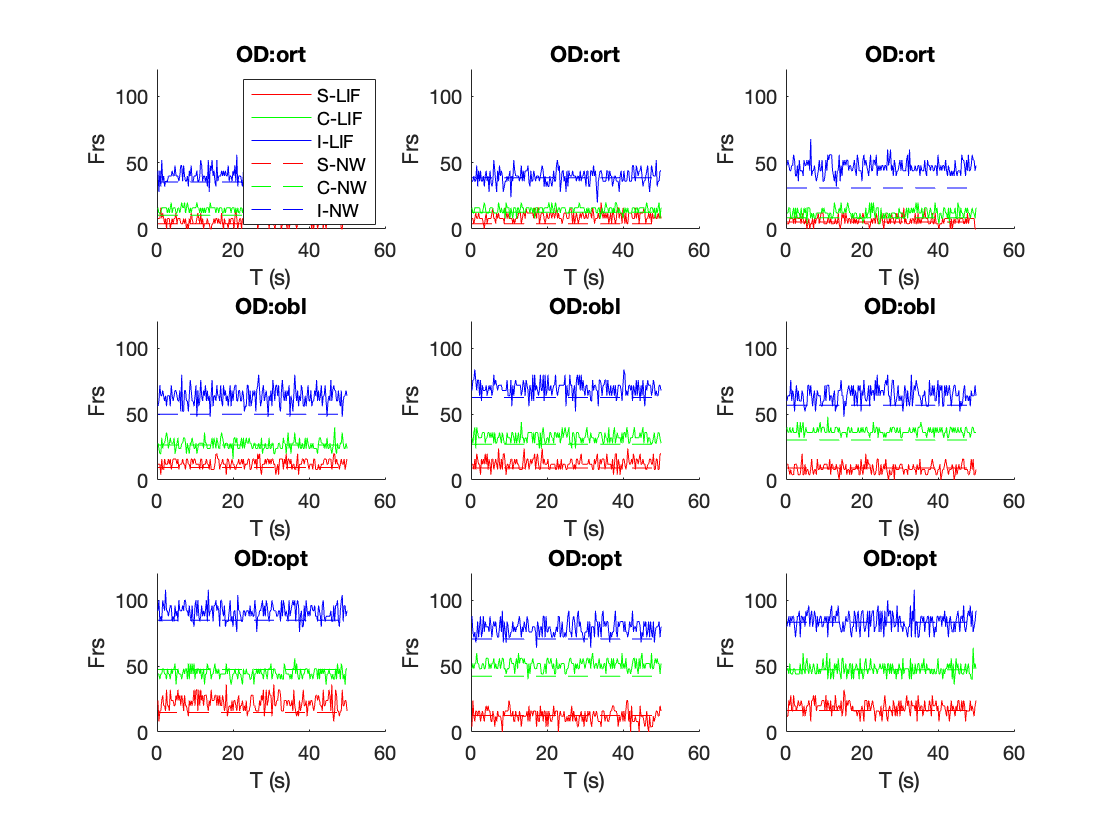

L4EPixU = 2.4739e+04

L4IPixU = 1.7621e+04

LDEInd = 10581

ans = 3

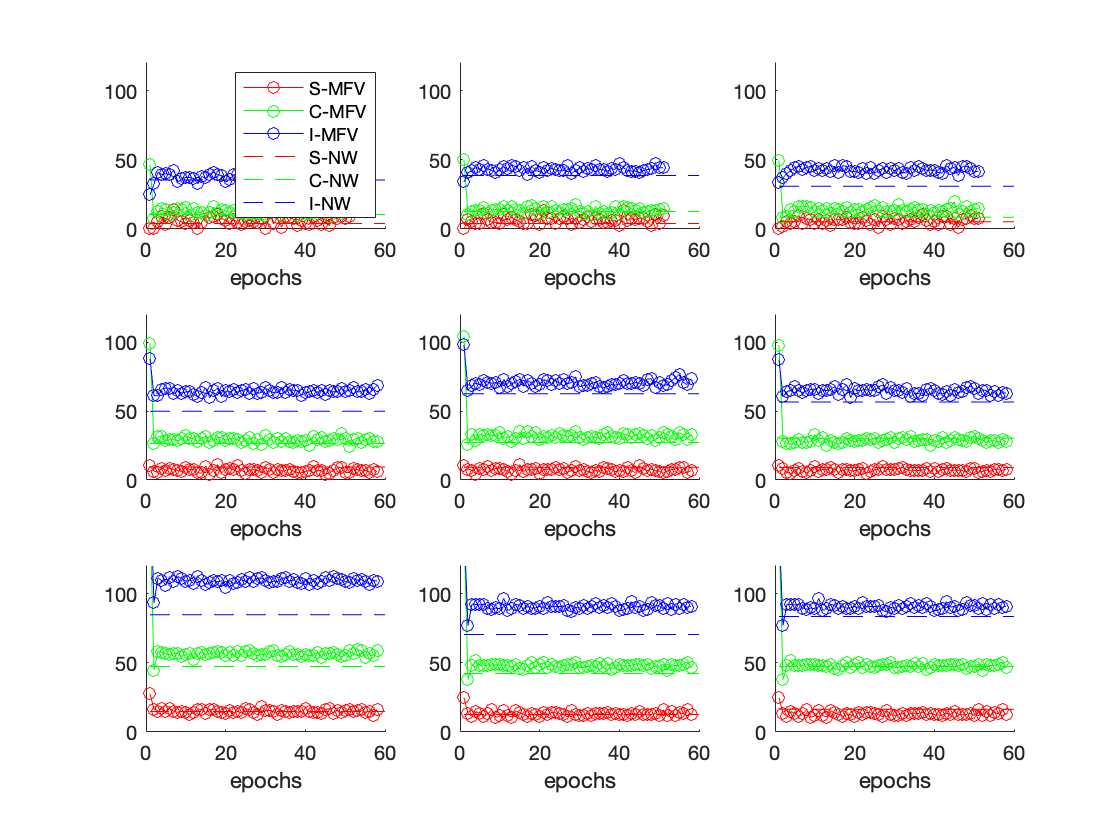

close all
TRcdSteps = 1/4:1/4:LIFSimuT/1e3;
DomName = {'ort','obl','opt'};
for PlotInd = 1:9
    SpRcdU = SpRcdAll{PlotInd};
    SpRcdU = cell2mat(SpRcdU');
    figure(1)
    % For each subplot
    subplot(3,3,PlotInd)
    hold on
    plot(TRcdSteps,SpRcdU(1,:)*LGNFreq,'r','DisplayName','S-LIF')
    plot(TRcdSteps,SpRcdU(2,:)*LGNFreq,'g','DisplayName','C-LIF')
    plot(TRcdSteps,SpRcdU(3,:)*LGNFreq,'b','DisplayName','I-LIF')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrSPixVec(PixIndList(PlotInd)),...
        'r--','DisplayName','S-NW')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrCPixVec(PixIndList(PlotInd)),...
        'g--','DisplayName','C-NW')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrIPixVec(PixIndList(PlotInd)),...
        'b--','DisplayName','I-NW')
    xlabel('T (s)'); ylabel('Frs'); ylim([0 120])
    title(['OD:', DomName{InputCtgrList(PlotInd)}])
    if PlotInd == 1
        legend
    end
    
    L4EPixU = L4EmfvUse(PixIndList(PlotInd))
    L4IPixU = L4ImfvUse(PixIndList(PlotInd))
    LDEInd = find(abs(L4ERcrd-L4EPixU)+abs(L4IRcrd-L4IPixU) == min(abs(L4ERcrd-L4EPixU)+abs(L4IRcrd-L4IPixU),[],'all'))
    InputCtgrList(PlotInd)
    if InputCtgrList(PlotInd) == 3
        fMFV = fLDE_OPT{LDEInd};
    elseif InputCtgrList(PlotInd) == 2
        fMFV = fLDE_OBL{LDEInd};
        
    elseif InputCtgrList(PlotInd) == 1
        fMFV = fLDE_ORT{LDEInd};
        
    end
    
    fMFV(fMFV<0) = eps;
    figure(2)
    subplot(3,3,PlotInd)
    hold on
    plot((fMFV(1,:)+fMFV(3,:))/2,'r','Marker','o','DisplayName','S-MFV')
    plot((fMFV(2,:)+fMFV(4,:))/2,'g','Marker','o','DisplayName','C-MFV')
    plot(fMFV(5,:),'b','Marker','o','DisplayName','I-MFV')
    plot(1:60,ones(size(1:60))*FrSPixVec(PixIndList(PlotInd)),...
        'r--','DisplayName','S-NW')
    plot(1:60,ones(size(1:60))*FrCPixVec(PixIndList(PlotInd)),...
        'g--','DisplayName','C-NW')
    plot(1:60,ones(size(1:60))*FrIPixVec(PixIndList(PlotInd)),...
        'b--','DisplayName','I-NW')
    xlabel('epochs');ylim([0 120]);xlim([0 60])
    if PlotInd == 1
        legend
    end
end